## Three image analysis methods

start_time = datetime('now')

start_time = datetime
   31-Mar-2025 00:22:55


save('start_time.mat', 'start_time');

### HSV Analysis - 5 MM

#### CAS Dataset

clc; clear; close all;

debug_mode = false;
imgs_proc = 0;
% Directories
orig_dir = 'C:\Users\andre\EE581-LandlideProj\data\original_dataset\';
output_dir = 'C:\Users\andre\Year5\EE581\Project\Datasets\Masks\HSV_CAS_5_Open\';
output_stats_dir = 'C:\Users\andre\EE581-LandlideProj\src\classical_methods\More_Stats_classical_methods.txt';

% Get list of folders inside directory
folders = dir(orig_dir);
folders = {folders([folders.isdir]).name}; % Get only folder names
folders = folders(~ismember(folders, {'.', '..', ...
    'Longxi River(UAV)','Tiburon Peninsula(Sentinel)'})); % Remove

% Set up stats storage
true_pos = cell(numel(folders),1); % Cell array - folder per row
false_pos = cell(numel(folders),1);
true_neg = cell(numel(folders),1);
false_neg = cell(numel(folders),1);
precision = cell(numel(folders),1);
recall = cell(numel(folders),1);
f1_score = cell(numel(folders),1);
accuracy = cell(numel(folders),1);
precision_per_set = cell(1,numel(folders));
recall_per_set = cell(1,numel(folders));
f1_score_per_set = cell(1,numel(folders));
accuracy_per_set = cell(1,numel(folders));
correct_landslide = cell(numel(folders),1);
correct_landslide_per_set = cell(numel(folders),1);

local_true_pos = cell(numel(folders),1);
local_false_pos = cell(numel(folders),1);
local_true_neg = cell(numel(folders),1);
local_false_neg = cell(numel(folders),1);
local_precision = cell(numel(folders),1);
local_recall = cell(numel(folders),1);
local_f1_score = cell(numel(folders),1);
local_accuracy = cell(numel(folders),1);
local_precision_per_set = cell(1,numel(folders));
local_recall_per_set = cell(1,numel(folders));
local_f1_score_per_set = cell(1,numel(folders));
local_accuracy_per_set = cell(1,numel(folders));

% Loop through each folder & assign zero array of its image count
for i=1:numel(folders)
    list_imgs = dir(fullfile(orig_dir, folders{i}, 'img', '*.tif')); % Get images
    list_lbls = dir(fullfile(orig_dir, folders{i}, 'label', '*.tif')); % Get images
    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else
        true_pos{i} = zeros(1,numel(list_imgs)); % Each cell contains image count
        false_pos{i} = zeros(1,numel(list_imgs));
        true_neg{i} = zeros(1,numel(list_imgs));
        false_neg{i} = zeros(1,numel(list_imgs));
        precision{i} = zeros(1,numel(list_imgs));
        recall{i} = zeros(1,numel(list_imgs));
        f1_score{i} = zeros(1,numel(list_imgs));
        accuracy{i} = zeros(1,numel(list_imgs));
        correct_landslide{i} = zeros(1,numel(list_imgs));
        
        local_true_pos{i} = zeros(1,numel(list_imgs));
        local_false_pos{i} = zeros(1,numel(list_imgs));
        local_true_neg{i} = zeros(1,numel(list_imgs));
        local_false_neg{i} = zeros(1,numel(list_imgs));
        local_precision{i} = zeros(1,numel(list_imgs));
        local_recall{i} = zeros(1,numel(list_imgs));
        local_f1_score{i} = zeros(1,numel(list_imgs));
        local_accuracy{i} = zeros(1,numel(list_imgs));
    end
end

% Iterate through each folder
t1 = datetime('now');
for i=1:numel(folders)
    % Directory
    img_dir = fullfile(orig_dir, folders{i}, 'img');
    lbl_dir = fullfile(orig_dir, folders{i}, 'label');

    % Get list of image and label files
    list_imgs = dir(fullfile(img_dir, '*.tif'));
    list_lbls = dir(fullfile(lbl_dir, '*.tif'));
    
    % Create folder to output masks
    if ~exist(fullfile(output_dir,folders{i}), 'dir')
        mkdir(output_dir,folders{i}); % Create folder if doesn't exist
    end

    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else

        % Iterate through each image (and label) of each folder
        t2 = datetime('now');
        for k = 1:numel(list_imgs)
            imgs_proc = imgs_proc + 1;
            % Directory
            img_path = fullfile(img_dir, list_imgs(k).name);
            lbl_path = fullfile(lbl_dir, list_lbls(k).name);
    
            % Load data and label
            img = double(imread(img_path));
            label = double(imread(lbl_path));
    
            % Normalize images
            if max(img(:)) > 1
                img = img / max(img(:)); % Scale to [0, 1]
            end
            if max(label(:)) > 1
                label = label / max(label(:)); % Scale to [0, 1]
            end

            % Binarise the label and invert it so landslied is 1
            
            label_temp = label;
            label_temp(label_temp == 255) = 1;
            label_bin = (label_temp(:,:,1) + label_temp(:,:,2) + label_temp(:,:,3)) > 0;
            label = 1 - label_bin;    
            img_hsv = rgb2hsv(img);
    
            % Super sample - use interpolation to increase resolution
            scale_factor = 2;
            img_hsv = imresize(img_hsv, scale_factor, 'bicubic'); % Think bicubic is the best
        
            % Convert into HSV format and exctract CHs
            R_CH = img(:,:,1); % Red CH
            G_CH = img(:,:,2); % Green CH
            B_CH = img(:,:,3); % Blue CH
            H_CH = img_hsv(:,:,1); % Hue CH
            S_CH = img_hsv(:,:,2); % Saturation CH
            V_CH = img_hsv(:,:,3); % Value CH
        
            % Reduce contrast
            H_mask = H_CH;
            H_mask = histeq(H_mask);
            H_thresh = 0.85;
            H_mask_bin = H_mask >= H_thresh;
            V_mask = V_CH;
            V_mask = histeq(V_mask);
            V_thresh = 0.85;
            V_mask_bin = V_mask >= V_thresh;
        
            % Match areas where landslides could be
            Mask_HV = H_mask_bin & V_mask_bin;
        
            % Remove very small patches by assuming they are like 'salt and pepper' noise
            Mask_HV_denoised = medfilt2(Mask_HV, [3 3]);
            
            % Fill gaps where landslides could be and return image to normal size
            Mask_HV_denoised_closed = imopen(Mask_HV_denoised, strel('disk', 5)); % Fill gaps
            mask = imresize(Mask_HV_denoised_closed, [size(img,1), size(img,2)], 'nearest');
              
            % Statistcally analyse results
            true_pos{i}(k) = sum(label & mask, 'all');
            false_pos{i}(k) = sum(label & ~mask, 'all');
            true_neg{i}(k) = sum(~label & ~mask, 'all');
            false_neg{i}(k) = sum(~label & mask, 'all');
            accuracy{i}(k) = (true_pos{i}(k) + true_neg{i}(k)) / (true_pos{i}(k) + true_neg{i}(k) + false_pos{i}(k) + false_neg{i}(k));
            if (true_pos{i}(k) + false_pos{i}(k)) == 0
                precision{i}(k) = 0;
            else
                precision{i}(k) = true_pos{i}(k) / (true_pos{i}(k) + false_pos{i}(k));
            end
            if (true_pos{i}(k) + false_neg{i}(k)) == 0
                recall{i}(k) = 0;
            else
                recall{i}(k) = true_pos{i}(k) / (true_pos{i}(k) + false_neg{i}(k));
            end
            if (precision{i}(k) + recall{i}(k)) == 0
                f1_score{i}(k) = 0;
            else
                f1_score{i}(k) = (2 * precision{i}(k) * recall{i}(k)) / (precision{i}(k) + recall{i}(k));
            end

            % Statistcally analyse results
            labelled_pixs = (label == 1); % Logical mask of landslide locations
            % Compare mask w/ label directly
            local_true_pos{i}(k) = sum(labelled_pixs & (mask == 1), 'all'); % Landlside in label & mask
            local_false_pos{i}(k) = sum(labelled_pixs & (mask == 0), 'all'); % Landlside in label & mask
            local_true_neg{i}(k) = sum(~labelled_pixs & (mask == 0), 'all'); % Landlside in label & mask
            local_false_neg{i}(k) = sum(~labelled_pixs & (mask == 1), 'all'); % Landlside in label & mask
            
            local_accuracy{i}(k) = (local_true_pos{i}(k) + local_true_neg{i}(k)) / (local_true_pos{i}(k) + local_true_neg{i}(k) + local_false_pos{i}(k) + local_false_neg{i}(k));
            if (local_true_pos{i}(k) + local_false_pos{i}(k)) == 0
                local_precision{i}(k) = 0;
            else
                local_precision{i}(k) = local_true_pos{i}(k) / (local_true_pos{i}(k) + local_false_pos{i}(k));
            end
            if (local_true_pos{i}(k) + local_false_neg{i}(k)) == 0
                local_recall{i}(k) = 0;
            else
                local_recall{i}(k) = local_true_pos{i}(k) / (local_true_pos{i}(k) + local_false_neg{i}(k));
            end
            if (local_precision{i}(k) + local_recall{i}(k)) == 0
                local_f1_score{i}(k) = 0;
            else
                local_f1_score{i}(k) = (2 * local_precision{i}(k) * local_recall{i}(k)) / (local_precision{i}(k) + local_recall{i}(k));
            end
            
            % Locally
            %[x_lbl, y_lbl] = find(label); % Locations within labelled
            %correct_pix = mask(sub2ind(size(mask), x_lbl, y_lbl)) == 1; % Logical array to compare - correctly identified 
            %fprintf("For %s Result=%.1f\n", folders{i}, local_true_pos{i}(k)/sum(label(:))*100);    
            correct_landslide{i}(k) = local_true_pos{i}(k)/sum(label(:))*100;
            output_file = fullfile(output_dir,folders{i},list_imgs(k).name);
            imwrite(mask,output_file);
        end
    end
    t3 = datetime('now');
    elapsedTime = seconds(t3-t2); % Cacluate elapsed times
    fprintf("%s --- Took %.1fs\n", folders{i} , elapsedTime);    
end
t3 = datetime('now');
elapsedTime = seconds(t3-t1); % Cacluate elapsed times
fprintf("Total processing time: %.1fs", elapsedTime);    

% Loop through each folder to compute stats
for i=1:numel(folders)
    list_imgs = dir(fullfile(orig_dir, folders{i}, 'img', '*.tif')); % Get images
    list_lbls = dir(fullfile(orig_dir, folders{i}, 'label', '*.tif')); % Get images
    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else
        % Create folder to output masks
        if ~exist(fullfile(output_dir,'Plots'), 'dir')
            mkdir(output_dir,'Plots');
        end
        %fprintf("For %s ||| Stats:\n", folders{i});

        % Calc stats per set
        correct_landslide_per_set{i} = mean((correct_landslide{i}));
        precision_per_set{i} = mean((precision{i}));
        recall_per_set{i} = mean((recall{i}));
        f1_score_per_set{i} = mean((f1_score{i}));
        accuracy_per_set{i} = mean((accuracy{i}));
        
        % Plot statistics
        figure;
        stem(correct_landslide{i}(:),'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Correct Pixels for %s", folders{i}));
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Correct_Landslide_%s.png',folders{i}));
        saveas(gcf, output_file); % Save current figure
        close(gcf); % Close figure to avoid memory usage
        figure;
        stem(accuracy{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Accuracy for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Accuracy_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(precision{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Precision for %s", folders{i}))
        grid on;
        ylim([0 100]);
        output_file = fullfile(output_dir,'Plots',sprintf('Precision_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(recall{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Recall for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Recall_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(f1_score{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("F1 Score for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('F1_Score_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(correct_landslide_per_set{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title("Correct Pixels per set");
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','Correct_Landslide.png');
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(accuracy_per_set{i}(:)*100,'.');
        xlabel('Set');
        ylabel('Percentage [%]');
        title("Accuracy per Set")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','Accuracy.png');
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(precision_per_set{i}(:)*100,'.');
        xlabel('Set');
        ylabel('Percentage [%]');
        title("Precision per Set")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','Precision.png');
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(recall_per_set{i}(:)*100,'.');
        xlabel('Set');
        ylabel('Percentage [%]');
        title("Recall per Set")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','Recall.png');
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(f1_score_per_set{i}(:)*100,'.');
        xlabel('Set');
        ylabel('Percentage [%]');
        title("F1 Score per Set")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','F1_Score.png');
        saveas(gcf, output_file);
        close(gcf); 

        % Calc stats per set
        local_precision_per_set{i} = mean((local_precision{i}));
        local_recall_per_set{i} = mean((local_recall{i}));
        local_f1_score_per_set{i} = mean((local_f1_score{i}));
        local_accuracy_per_set{i} = mean((local_accuracy{i}));
        
        % Plot statistics
        figure;
        stem(local_accuracy{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Accuracy for %s (Landslide Pixels)", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Accuracy_Pix_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(local_precision{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Precision for %s (Landslide Pixels)", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Precision_Pix_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(local_recall{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Recall for %s (Landslide Pixels)", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Recall_Pix_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(local_f1_score{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("F1 Score for %s (Landslide Pixels)", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('F1_Score_Pix_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(local_accuracy_per_set{i}(:)*100,'.');
        xlabel('Set');
        ylabel('Percentage [%]');
        title("Accuracy per Set (Landslide Pixels)")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','Accuracy_Pix.png');
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(local_precision_per_set{i}(:)*100,'.');
        xlabel('Set');
        ylabel('Percentage [%]');
        title("Precision per Set (Landslide Pixels)")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','Precision_Pix.png');
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(local_recall_per_set{i}(:)*100,'.');
        xlabel('Set');
        ylabel('Percentage [%]');
        title("Recall per Set (Landslide Pixels)")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','Recall_Pix.png');
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(local_f1_score_per_set{i}(:)*100,'.');
        xlabel('Set');
        ylabel('Percentage [%]');
        title("F1 Score per Set (Landslide Pixels)")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','F1_Score_Pix.png');
        saveas(gcf, output_file);
        close(gcf); 
    end
end

overall_correct_landslide_hsv_cas_5_closing = mean(cell2mat(correct_landslide_per_set))
overall_precision_hsv_cas_5_closing = mean(cell2mat(precision_per_set))
overall_pix_precision_hsv_cas_5_closing = mean(cell2mat(local_precision_per_set))
overall_recall_hsv_cas_5_closing = mean(cell2mat(recall_per_set))
overall_pix_recall_hsv_cas_5_closing = mean(cell2mat(local_recall_per_set))
overall_f1_score_hsv_cas_5_closing = mean(cell2mat(f1_score_per_set))
overall_pix_f1_score_hsv_cas_5_closing = mean(cell2mat(local_f1_score_per_set))
overall_accuracy_hsv_cas_5_closing = mean(cell2mat(accuracy_per_set))
overall_pix_accuracy_hsv_cas_5_closing = mean(cell2mat(local_accuracy_per_set))

% Open file
output_stats_id = fopen(output_stats_dir, 'a');
% Write seperator line
fprintf(output_stats_id, '----- HSV CAS 5 Opening -----\n'); 
% Log data
fprintf(output_stats_id, 'overall_correct_landslide_hsv_cas_5_closing = %.5f\n', overall_correct_landslide_hsv_cas_5_closing);
fprintf(output_stats_id, 'overall_precision_hsv_cas_5_closing = %.5f\n', overall_precision_hsv_cas_5_closing);
fprintf(output_stats_id, 'overall_pix_precision_hsv_cas_5_closing = %.5f\n', overall_pix_precision_hsv_cas_5_closing);
fprintf(output_stats_id, 'overall_recall_hsv_cas_5_closing = %.5f\n', overall_recall_hsv_cas_5_closing);
fprintf(output_stats_id, 'overall_pix_recall_hsv_cas_5_closing = %.5f\n', overall_pix_recall_hsv_cas_5_closing);
fprintf(output_stats_id, 'overall_f1_score_hsv_cas_5_closing = %.5f\n', overall_f1_score_hsv_cas_5_closing);
fprintf(output_stats_id, 'overall_pix_f1_score_hsv_cas_5_closing = %.5f\n', overall_pix_f1_score_hsv_cas_5_closing);
fprintf(output_stats_id, 'overall_accuracy_hsv_cas_5_closing = %.5f\n', overall_accuracy_hsv_cas_5_closing);
fprintf(output_stats_id, 'overall_pix_accuracy_hsv_cas_5_closing = %.5f\n', overall_pix_accuracy_hsv_cas_5_closing);
arr_correct_landslide_per_set = cell2mat(correct_landslide_per_set');
fprintf(output_stats_id, 'Correct landslide per set: ');
fprintf(output_stats_id, '%.5f, ', arr_correct_landslide_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_correct_landslide_per_set(end));
arr_precision_per_set = cell2mat(precision_per_set);
fprintf(output_stats_id, 'Precision per set: ');
fprintf(output_stats_id, '%.5f, ', arr_precision_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_precision_per_set(end));
arr_local_precision_per_set = cell2mat(local_precision_per_set);
fprintf(output_stats_id, 'Local precision per set: ');
fprintf(output_stats_id, '%.5f, ', arr_local_precision_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_local_precision_per_set(end));
arr_recall_per_set = cell2mat(recall_per_set);
fprintf(output_stats_id, 'Recall per set: ');
fprintf(output_stats_id, '%.5f, ', arr_recall_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_recall_per_set(end));
arr_local_recall_per_set = cell2mat(local_recall_per_set)
fprintf(output_stats_id, 'Local recall per set: ');
fprintf(output_stats_id, '%.5f, ', arr_local_recall_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_local_recall_per_set(end));
arr_f1_score_per_set = cell2mat(f1_score_per_set);
fprintf(output_stats_id, 'F1 score per set: ');
fprintf(output_stats_id, '%.5f, ', arr_f1_score_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_f1_score_per_set(end));
arr_local_f1_score_per_set = cell2mat(local_f1_score_per_set);
fprintf(output_stats_id, 'Local F1 score per set: ');
fprintf(output_stats_id, '%.5f, ', arr_local_f1_score_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_local_f1_score_per_set(end));
arr_accuracy_per_set = cell2mat(accuracy_per_set);
fprintf(output_stats_id, 'Accuracy score per set: ');
fprintf(output_stats_id, '%.5f, ', arr_accuracy_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_accuracy_per_set(end));
arr_local_accuracy_per_set = cell2mat(local_accuracy_per_set);
fprintf(output_stats_id, 'Local accuracy score per set: ');
fprintf(output_stats_id, '%.5f, ', arr_local_accuracy_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_local_accuracy_per_set(end));
fprintf(output_stats_id, 'Duration of processing: %.1fs\n', elapsedTime);
% Close file
fclose(output_stats_id);

% Clear workspace to save RAM
clear all

#### Sense Dataset

clc; clear; close all;

imgs_proc = 0;

% Directories
orig_dir = 'C:\Users\andre\Year5\EE581\Project\Datasets\archive\TrainData\';
output_dir = 'C:\Users\andre\Year5\EE581\Project\Datasets\Masks\HSV_Sense_5_Open\';
output_stats_dir = 'C:\Users\andre\EE581-LandlideProj\src\classical_methods\More_Stats_classical_methods.txt';

% Get list of folders inside directory
folders = dir(orig_dir);
folders = {folders([folders.isdir]).name}; % Get only folder names
folders = folders(~ismember(folders, {'.', '..'})); % Remove

% Set up stats storage
% Assign zero array of its image count
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels
% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count');
else
    true_pos = zeros(1,numel(list_imgs));
    false_pos = zeros(1,numel(list_imgs));
    true_neg = zeros(1,numel(list_imgs));
    false_neg = zeros(1,numel(list_imgs));
    precision = zeros(1,numel(list_imgs));
    recall = zeros(1,numel(list_imgs));
    f1_score = zeros(1,numel(list_imgs));
    accuracy = zeros(1,numel(list_imgs));
    correct_landslide = zeros(1,numel(list_imgs));
        
    local_true_pos = zeros(1,numel(list_imgs));
    local_false_pos = zeros(1,numel(list_imgs));
    local_true_neg = zeros(1,numel(list_imgs));
    local_false_neg = zeros(1,numel(list_imgs));
    local_precision = zeros(1,numel(list_imgs));
    local_recall = zeros(1,numel(list_imgs));
    local_f1_score = zeros(1,numel(list_imgs));
    local_accuracy = zeros(1,numel(list_imgs));
end

% Go through through folder
t1 = datetime('now');
% Get list of image and label files
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels

% Create folder for all outputs
if ~exist(output_dir,'dir')
    mkdir(output_dir); % Create folder if doesn't exist
end

% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count for folder: %s', folders{i});
else
    % Iterate through each image (and label) of each folder
    t2 = datetime('now');

    % Create folder to output masks
    if ~exist(fullfile(output_dir,'Mask'),'dir')
        mkdir(output_dir,'Mask'); % Create folder if doesn't exist
    end

    for k = 1:numel(list_imgs)
        imgs_proc = imgs_proc + 1;
        % Full path
        img_path = fullfile(orig_dir, folders{1}, list_imgs(k).name);
        lbl_path = fullfile(orig_dir, folders{2}, list_lbls(k).name);

        % Read HDF5 data
        img_info = h5info(img_path);
        img_name = img_info.Datasets(1).Name;
        img_chs = h5read(img_path, ['/' img_name]);
            
        label_info = h5info(lbl_path);
        label_name = label_info.Datasets(1).Name;
        label = h5read(lbl_path, ['/' label_name]);

        % Binarise image
        label = label > 0;

        % Extract channels
        R_CH = squeeze(img_chs(4,:,:));
        G_CH = squeeze(img_chs(3,:,:));
        B_CH = squeeze(img_chs(2,:,:));

        % Combine into an RGB image & label
        img = double(cat(3, R_CH, G_CH, B_CH));
        
        % Normalize images
        if max(img(:)) > 1
            img = img / max(img(:)); % Scale to [0, 1]
        end
        
        img_hsv = rgb2hsv(img);
            
        % Super sample - use interpolation to increase resolution
        scale_factor = 2;
        img_hsv = imresize(img_hsv, scale_factor, 'bicubic'); % Think bicubic is the best
        
        % Convert into HSV format and exctract CHs
        H_CH = img_hsv(:,:,1); % Hue CH
        S_CH = img_hsv(:,:,2); % Saturation CH
        V_CH = img_hsv(:,:,3); % Value CH
        
        % Reduce contrast
        H_mask = H_CH;
        H_mask = histeq(H_mask);
        H_thresh = 0.85;
        H_mask_bin = H_mask >= H_thresh;
        V_mask = V_CH;
        V_mask = histeq(V_mask);
        V_thresh = 0.85;
        V_mask_bin = V_mask >= V_thresh;
        
        % Match areas where landslides could be
        Mask_HV = H_mask_bin & V_mask_bin;
        
        % Remove very small patches by assuming they are like 'salt and pepper' noise
        Mask_HV_denoised = medfilt2(Mask_HV, [3 3]);
            
        % Fill gaps where landslides could be and return image to normal size
        Mask_HV_denoised_closed = imopen(Mask_HV_denoised, strel('disk', 5)); % Fill gaps
        mask = imresize(Mask_HV_denoised_closed, [size(img,1), size(img,2)], 'nearest');
    
        % Statistcally analyse results
        true_pos(k) = sum(label & mask, 'all');
        false_pos(k) = sum(label & ~mask, 'all');
        true_neg(k) = sum(~label & ~mask, 'all');
        false_neg(k) = sum(~label & mask, 'all');
        accuracy(k) = (true_pos(k) + true_neg(k)) / (true_pos(k) + true_neg(k) + false_pos(k) + false_neg(k));
        if (true_pos(k) + false_pos(k)) == 0
            precision(k) = 0;
        else
            precision(k) = true_pos(k) / (true_pos(k) + false_pos(k));
        end
        if (true_pos(k) + false_neg(k)) == 0
            recall(k) = 0;
        else
            recall(k) = true_pos(k) / (true_pos(k) + false_neg(k));
        end
        if (precision(k) + recall(k)) == 0
            f1_score(k) = 0;
        else
            f1_score(k) = (2 * precision(k) * recall(k)) / (precision(k) + recall(k));
        end

        % Statistcally analyse results
        labelled_pixs = (label == 1); % Logical mask of landslide locations
        % Compare mask w/ label directly
        local_true_pos(k) = sum(labelled_pixs & (mask == 1), 'all'); % Landlside in label & mask
        local_false_pos(k) = sum(labelled_pixs & (mask == 0), 'all'); % Landlside in label & mask
        local_true_neg(k) = sum(~labelled_pixs & (mask == 0), 'all'); % Landlside in label & mask
        local_false_neg(k) = sum(~labelled_pixs & (mask == 1), 'all'); % Landlside in label & mask
        
        local_accuracy(k) = (local_true_pos(k) + local_true_neg(k)) / (local_true_pos(k) + local_true_neg(k) + local_false_pos(k) + local_false_neg(k));
        if (local_true_pos(k) + local_false_pos(k)) == 0
            local_precision(k) = 0;
        else
            local_precision(k) = local_true_pos(k) / (local_true_pos(k) + local_false_pos(k));
        end

        if (local_true_pos(k) + local_false_neg(k)) == 0
            local_recall(k) = 0;
        else
            local_recall(k) = local_true_pos(k) / (local_true_pos(k) + local_false_neg(k));
        end
        if (local_precision(k) + local_recall(k)) == 0
            local_f1_score(k) = 0;
        else
            local_f1_score(k) = (2 * local_precision(k) * local_recall(k)) / (local_precision(k) + local_recall(k));
        end

        % Locally
        %[x_lbl, y_lbl] = find(label); % Locations within labelled
        %correct_pix = mask(sub2ind(size(mask), x_lbl, y_lbl)) == 1; % Logical array to compare - correctly identified 
        %fprintf("For %s Result=%.1f\n", folders, local_true_pos(k)/sum(label(:))*100);    
        if sum(label(:)) == 0
            if local_true_pos(k) == 0
                correct_landslide(k) = 100; % ---
            else
                correct_landslide(k) = 0;
            end
        else
            correct_landslide(k) = local_true_pos(k)/sum(label(:))*100;
        end
        mask_name = split(list_imgs(k).name, '.');
        mask_name = [mask_name{1}, '.jpg'];
        output_file = fullfile(output_dir,'Mask',mask_name);
        imwrite(mask,output_file);
    end
end

t3 = datetime('now');
elapsedTime = seconds(t3-t1); % Cacluate elapsed times
fprintf("Total processing time: %.1fs", elapsedTime);    

% Go through folder to compute stats
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels
% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count');
else

    % Create folder to output masks
    if ~exist(fullfile(output_dir,'Plots'), 'dir')
        mkdir(output_dir,'Plots');
    end

    % Plot statistics
    figure;
    stem(correct_landslide,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Correct Pixels");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Correct_Landslide.png');
    saveas(gcf, output_file); % Save current figure
    close(gcf); % Close figure to avoid memory usage
    figure;
    stem(accuracy*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Accuracy");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Accuracy.png');
    saveas(gcf, output_file);
    close(gcf); 
    figure;
    stem(precision*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Precision");
    grid on;
    ylim([0 100]);
    output_file = fullfile(output_dir,'Plots','Precision.png');
    saveas(gcf, output_file);
    close(gcf); 
    figure;
    stem(recall*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Recall");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Recall.png');
    saveas(gcf, output_file);
    close(gcf); 
    figure;
    stem(f1_score*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("F1 Score");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','F1_Score.png');
    saveas(gcf, output_file);
    close(gcf); 
    
    % Plot statistics
    figure;
    stem(local_accuracy*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Accuracy (Landslide Pixels)");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Accuracy_Pix.png');
    saveas(gcf, output_file);
    close(gcf);
    figure;
    stem(local_precision*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Precision (Landslide Pixels)");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Precision_Pix.png');
    saveas(gcf, output_file);
    close(gcf);
    figure;
    stem(local_recall*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Recall (Landslide Pixels)");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Recall_Pix.png');
    saveas(gcf, output_file);
    close(gcf);
    figure;
    stem(local_f1_score*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("F1 Score (Landslide Pixels)");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','F1_Score_Pix.png');
    saveas(gcf, output_file);
    close(gcf);
end

overall_correct_landslide_hsv_sense_cas_5_closing = mean(correct_landslide);
overall_precision_hsv_sense_cas_5_closing = mean(precision);
overall_pix_precision_hsv_sense_cas_5_closing = mean(local_precision);
overall_recall_hsv_sense_cas_5_closing = mean(recall);
overall_pix_recall_hsv_sense_cas_5_closing = mean(local_recall);
overall_f1_score_hsv_sense_cas_5_closing = mean(f1_score);
overall_pix_f1_score_hsv_sense_cas_5_closing = mean(local_f1_score);
overall_accuracy_hsv_sense_cas_5_closing = mean(accuracy);
overall_pix_accuracy_hsv_sense_cas_5_closing = mean(local_accuracy);

% Open file
output_stats_id = fopen(output_stats_dir, 'a');
% Write seperator line
fprintf(output_stats_id, '----- HSV Sense 5 Opening -----\n'); 
% Log data
fprintf(output_stats_id, 'overall_correct_landslide_hsv_sense_cas_5_closing = %.5f\n', overall_correct_landslide_hsv_sense_cas_5_closing);
fprintf(output_stats_id, 'overall_precision_hsv_sense_cas_5_closing = %.5f\n', overall_precision_hsv_sense_cas_5_closing);
fprintf(output_stats_id, 'overall_pix_precision_hsv_sense_cas_5_closing = %.5f\n', overall_pix_precision_hsv_sense_cas_5_closing);
fprintf(output_stats_id, 'overall_recall_hsv_sense_cas_5_closing = %.5f\n', overall_recall_hsv_sense_cas_5_closing);
fprintf(output_stats_id, 'overall_pix_recall_hsv_sense_cas_5_closing = %.5f\n', overall_pix_recall_hsv_sense_cas_5_closing);
fprintf(output_stats_id, 'overall_f1_score_hsv_sense_cas_5_closing = %.5f\n', overall_f1_score_hsv_sense_cas_5_closing);
fprintf(output_stats_id, 'overall_pix_f1_score_hsv_sense_cas_5_closing = %.5f\n', overall_pix_f1_score_hsv_sense_cas_5_closing);
fprintf(output_stats_id, 'overall_accuracy_hsv_sense_cas_5_closing = %.5f\n', overall_accuracy_hsv_sense_cas_5_closing);
fprintf(output_stats_id, 'overall_pix_accuracy_hsv_sense_cas_5_closing = %.5f\n', overall_pix_accuracy_hsv_sense_cas_5_closing);
fprintf(output_stats_id, 'Duration of processing: %.1fs\n', elapsedTime);
% Close file
fclose(output_stats_id);

end_time_hsv_5_close = datetime('now');
save('end_time_hsv_5_close.mat', 'end_time_hsv_5_close');

clear all;

### HSV Analysis - 7 MM

#### CAS Dataset

clc; clear; close all;

debug_mode = false;
imgs_proc = 0;
% Directories
orig_dir = 'C:\Users\andre\EE581-LandlideProj\data\original_dataset\';
output_dir = 'C:\Users\andre\Year5\EE581\Project\Datasets\Masks\HSV_CAS_7_Open\';
output_stats_dir = 'C:\Users\andre\EE581-LandlideProj\src\classical_methods\More_Stats_classical_methods.txt';

% Get list of folders inside directory
folders = dir(orig_dir);
folders = {folders([folders.isdir]).name}; % Get only folder names
folders = folders(~ismember(folders, {'.', '..', ...
    'Longxi River(UAV)','Tiburon Peninsula(Sentinel)'})); % Remove

% Set up stats storage
true_pos = cell(numel(folders),1); % Cell array - folder per row
false_pos = cell(numel(folders),1);
true_neg = cell(numel(folders),1);
false_neg = cell(numel(folders),1);
precision = cell(numel(folders),1);
recall = cell(numel(folders),1);
f1_score = cell(numel(folders),1);
accuracy = cell(numel(folders),1);
precision_per_set = cell(1,numel(folders));
recall_per_set = cell(1,numel(folders));
f1_score_per_set = cell(1,numel(folders));
accuracy_per_set = cell(1,numel(folders));
correct_landslide = cell(numel(folders),1);
correct_landslide_per_set = cell(numel(folders),1);

local_true_pos = cell(numel(folders),1);
local_false_pos = cell(numel(folders),1);
local_true_neg = cell(numel(folders),1);
local_false_neg = cell(numel(folders),1);
local_precision = cell(numel(folders),1);
local_recall = cell(numel(folders),1);
local_f1_score = cell(numel(folders),1);
local_accuracy = cell(numel(folders),1);
local_precision_per_set = cell(1,numel(folders));
local_recall_per_set = cell(1,numel(folders));
local_f1_score_per_set = cell(1,numel(folders));
local_accuracy_per_set = cell(1,numel(folders));

% Loop through each folder & assign zero array of its image count
for i=1:numel(folders)
    list_imgs = dir(fullfile(orig_dir, folders{i}, 'img', '*.tif')); % Get images
    list_lbls = dir(fullfile(orig_dir, folders{i}, 'label', '*.tif')); % Get images
    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else
        true_pos{i} = zeros(1,numel(list_imgs)); % Each cell contains image count
        false_pos{i} = zeros(1,numel(list_imgs));
        true_neg{i} = zeros(1,numel(list_imgs));
        false_neg{i} = zeros(1,numel(list_imgs));
        precision{i} = zeros(1,numel(list_imgs));
        recall{i} = zeros(1,numel(list_imgs));
        f1_score{i} = zeros(1,numel(list_imgs));
        accuracy{i} = zeros(1,numel(list_imgs));
        correct_landslide{i} = zeros(1,numel(list_imgs));
        
        local_true_pos{i} = zeros(1,numel(list_imgs));
        local_false_pos{i} = zeros(1,numel(list_imgs));
        local_true_neg{i} = zeros(1,numel(list_imgs));
        local_false_neg{i} = zeros(1,numel(list_imgs));
        local_precision{i} = zeros(1,numel(list_imgs));
        local_recall{i} = zeros(1,numel(list_imgs));
        local_f1_score{i} = zeros(1,numel(list_imgs));
        local_accuracy{i} = zeros(1,numel(list_imgs));
    end
end

% Iterate through each folder
t1 = datetime('now');
for i=1:numel(folders)
    % Directory
    img_dir = fullfile(orig_dir, folders{i}, 'img');
    lbl_dir = fullfile(orig_dir, folders{i}, 'label');

    % Get list of image and label files
    list_imgs = dir(fullfile(img_dir, '*.tif'));
    list_lbls = dir(fullfile(lbl_dir, '*.tif'));
    
    % Create folder to output masks
    if ~exist(fullfile(output_dir,folders{i}), 'dir')
        mkdir(output_dir,folders{i}); % Create folder if doesn't exist
    end

    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else

        % Iterate through each image (and label) of each folder
        t2 = datetime('now');
        for k = 1:numel(list_imgs)
            imgs_proc = imgs_proc + 1;
            % Directory
            img_path = fullfile(img_dir, list_imgs(k).name);
            lbl_path = fullfile(lbl_dir, list_lbls(k).name);
    
            % Load data and label
            img = double(imread(img_path));
            label = double(imread(lbl_path));
    
            % Normalize images
            if max(img(:)) > 1
                img = img / max(img(:)); % Scale to [0, 1]
            end
            if max(label(:)) > 1
                label = label / max(label(:)); % Scale to [0, 1]
            end

            % Binarise the label and invert it so landslied is 1
            
            label_temp = label;
            label_temp(label_temp == 255) = 1;
            label_bin = (label_temp(:,:,1) + label_temp(:,:,2) + label_temp(:,:,3)) > 0;
            label = 1 - label_bin;    
            img_hsv = rgb2hsv(img);
    
            % Super sample - use interpolation to increase resolution
            scale_factor = 2;
            img_hsv = imresize(img_hsv, scale_factor, 'bicubic'); % Think bicubic is the best
        
            % Convert into HSV format and exctract CHs
            R_CH = img(:,:,1); % Red CH
            G_CH = img(:,:,2); % Green CH
            B_CH = img(:,:,3); % Blue CH
            H_CH = img_hsv(:,:,1); % Hue CH
            S_CH = img_hsv(:,:,2); % Saturation CH
            V_CH = img_hsv(:,:,3); % Value CH
        
            % Reduce contrast
            H_mask = H_CH;
            H_mask = histeq(H_mask);
            H_thresh = 0.85;
            H_mask_bin = H_mask >= H_thresh;
            V_mask = V_CH;
            V_mask = histeq(V_mask);
            V_thresh = 0.85;
            V_mask_bin = V_mask >= V_thresh;
        
            % Match areas where landslides could be
            Mask_HV = H_mask_bin & V_mask_bin;
        
            % Remove very small patches by assuming they are like 'salt and pepper' noise
            Mask_HV_denoised = medfilt2(Mask_HV, [3 3]);
            
            % Fill gaps where landslides could be and return image to normal size
            Mask_HV_denoised_closed = imopen(Mask_HV_denoised, strel('disk', 7)); % Fill gaps
            mask = imresize(Mask_HV_denoised_closed, [size(img,1), size(img,2)], 'nearest');
    
            % Statistcally analyse results
            true_pos{i}(k) = sum(label & mask, 'all');
            false_pos{i}(k) = sum(label & ~mask, 'all');
            true_neg{i}(k) = sum(~label & ~mask, 'all');
            false_neg{i}(k) = sum(~label & mask, 'all');
            accuracy{i}(k) = (true_pos{i}(k) + true_neg{i}(k)) / (true_pos{i}(k) + true_neg{i}(k) + false_pos{i}(k) + false_neg{i}(k));
            if (true_pos{i}(k) + false_pos{i}(k)) == 0
                precision{i}(k) = 0;
            else
                precision{i}(k) = true_pos{i}(k) / (true_pos{i}(k) + false_pos{i}(k));
            end
            if (true_pos{i}(k) + false_neg{i}(k)) == 0
                recall{i}(k) = 0;
            else
                recall{i}(k) = true_pos{i}(k) / (true_pos{i}(k) + false_neg{i}(k));
            end
            if (precision{i}(k) + recall{i}(k)) == 0
                f1_score{i}(k) = 0;
            else
                f1_score{i}(k) = (2 * precision{i}(k) * recall{i}(k)) / (precision{i}(k) + recall{i}(k));
            end

            % Statistcally analyse results
            labelled_pixs = (label == 1); % Logical mask of landslide locations
            % Compare mask w/ label directly
            local_true_pos{i}(k) = sum(labelled_pixs & (mask == 1), 'all'); % Landlside in label & mask
            local_false_pos{i}(k) = sum(labelled_pixs & (mask == 0), 'all'); % Landlside in label & mask
            local_true_neg{i}(k) = sum(~labelled_pixs & (mask == 0), 'all'); % Landlside in label & mask
            local_false_neg{i}(k) = sum(~labelled_pixs & (mask == 1), 'all'); % Landlside in label & mask
            
            local_accuracy{i}(k) = (local_true_pos{i}(k) + local_true_neg{i}(k)) / (local_true_pos{i}(k) + local_true_neg{i}(k) + local_false_pos{i}(k) + local_false_neg{i}(k));
            if (local_true_pos{i}(k) + local_false_pos{i}(k)) == 0
                local_precision{i}(k) = 0;
            else
                local_precision{i}(k) = local_true_pos{i}(k) / (local_true_pos{i}(k) + local_false_pos{i}(k));
            end
            if (local_true_pos{i}(k) + local_false_neg{i}(k)) == 0
                local_recall{i}(k) = 0;
            else
                local_recall{i}(k) = local_true_pos{i}(k) / (local_true_pos{i}(k) + local_false_neg{i}(k));
            end
            if (local_precision{i}(k) + local_recall{i}(k)) == 0
                local_f1_score{i}(k) = 0;
            else
                local_f1_score{i}(k) = (2 * local_precision{i}(k) * local_recall{i}(k)) / (local_precision{i}(k) + local_recall{i}(k));
            end
            
            % Locally
            %[x_lbl, y_lbl] = find(label); % Locations within labelled
            %correct_pix = mask(sub2ind(size(mask), x_lbl, y_lbl)) == 1; % Logical array to compare - correctly identified 
            %fprintf("For %s Result=%.1f\n", folders{i}, local_true_pos{i}(k)/sum(label(:))*100);    
            correct_landslide{i}(k) = local_true_pos{i}(k)/sum(label(:))*100;
            output_file = fullfile(output_dir,folders{i},list_imgs(k).name);
            imwrite(mask,output_file);
        end
    end
    t3 = datetime('now');
    elapsedTime = seconds(t3-t2); % Cacluate elapsed times
    fprintf("%s --- Took %.1fs\n", folders{i} , elapsedTime);    
end
t3 = datetime('now');
elapsedTime = seconds(t3-t1); % Cacluate elapsed times
fprintf("Total processing time: %.1fs", elapsedTime);    

% Loop through each folder to compute stats
for i=1:numel(folders)
    list_imgs = dir(fullfile(orig_dir, folders{i}, 'img', '*.tif')); % Get images
    list_lbls = dir(fullfile(orig_dir, folders{i}, 'label', '*.tif')); % Get images
    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else
        % Create folder to output masks
        if ~exist(fullfile(output_dir,'Plots'), 'dir')
            mkdir(output_dir,'Plots');
        end
        %fprintf("For %s ||| Stats:\n", folders{i});

        % Calc stats per set
        correct_landslide_per_set{i} = mean((correct_landslide{i}));
        precision_per_set{i} = mean((precision{i}));
        recall_per_set{i} = mean((recall{i}));
        f1_score_per_set{i} = mean((f1_score{i}));
        accuracy_per_set{i} = mean((accuracy{i}));
        
        % Plot statistics
        figure;
        stem(correct_landslide{i}(:),'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Correct Pixels for %s", folders{i}));
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Correct_Landslide_%s.png',folders{i}));
        saveas(gcf, output_file); % Save current figure
        close(gcf); % Close figure to avoid memory usage
        figure;
        stem(accuracy{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Accuracy for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Accuracy_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(precision{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Precision for %s", folders{i}))
        grid on;
        ylim([0 100]);
        output_file = fullfile(output_dir,'Plots',sprintf('Precision_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(recall{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Recall for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Recall_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(f1_score{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("F1 Score for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('F1_Score_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(correct_landslide_per_set{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title("Correct Pixels per set");
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','Correct_Landslide.png');
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(accuracy_per_set{i}(:)*100,'.');
        xlabel('Set');
        ylabel('Percentage [%]');
        title("Accuracy per Set")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','Accuracy.png');
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(precision_per_set{i}(:)*100,'.');
        xlabel('Set');
        ylabel('Percentage [%]');
        title("Precision per Set")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','Precision.png');
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(recall_per_set{i}(:)*100,'.');
        xlabel('Set');
        ylabel('Percentage [%]');
        title("Recall per Set")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','Recall.png');
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(f1_score_per_set{i}(:)*100,'.');
        xlabel('Set');
        ylabel('Percentage [%]');
        title("F1 Score per Set")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','F1_Score.png');
        saveas(gcf, output_file);
        close(gcf); 

        % Calc stats per set
        local_precision_per_set{i} = mean((local_precision{i}));
        local_recall_per_set{i} = mean((local_recall{i}));
        local_f1_score_per_set{i} = mean((local_f1_score{i}));
        local_accuracy_per_set{i} = mean((local_accuracy{i}));
        
        % Plot statistics
        figure;
        stem(local_accuracy{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Accuracy for %s (Landslide Pixels)", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Accuracy_Pix_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(local_precision{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Precision for %s (Landslide Pixels)", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Precision_Pix_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(local_recall{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Recall for %s (Landslide Pixels)", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Recall_Pix_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(local_f1_score{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("F1 Score for %s (Landslide Pixels)", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('F1_Score_Pix_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(local_accuracy_per_set{i}(:)*100,'.');
        xlabel('Set');
        ylabel('Percentage [%]');
        title("Accuracy per Set (Landslide Pixels)")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','Accuracy_Pix.png');
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(local_precision_per_set{i}(:)*100,'.');
        xlabel('Set');
        ylabel('Percentage [%]');
        title("Precision per Set (Landslide Pixels)")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','Precision_Pix.png');
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(local_recall_per_set{i}(:)*100,'.');
        xlabel('Set');
        ylabel('Percentage [%]');
        title("Recall per Set (Landslide Pixels)")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','Recall_Pix.png');
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(local_f1_score_per_set{i}(:)*100,'.');
        xlabel('Set');
        ylabel('Percentage [%]');
        title("F1 Score per Set (Landslide Pixels)")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','F1_Score_Pix.png');
        saveas(gcf, output_file);
        close(gcf); 
    end
end

overall_correct_landslide_hsv_cas_7_closing = mean(cell2mat(correct_landslide_per_set))
overall_precision_hsv_cas_7_closing = mean(cell2mat(precision_per_set))
overall_pix_precision_hsv_cas_7_closing = mean(cell2mat(local_precision_per_set))
overall_recall_hsv_cas_7_closing = mean(cell2mat(recall_per_set))
overall_pix_recall_hsv_cas_7_closing = mean(cell2mat(local_recall_per_set))
overall_f1_score_hsv_cas_7_closing = mean(cell2mat(f1_score_per_set))
overall_pix_f1_score_hsv_cas_7_closing = mean(cell2mat(local_f1_score_per_set))
overall_accuracy_hsv_cas_7_closing = mean(cell2mat(accuracy_per_set))
overall_pix_accuracy_hsv_cas_7_closing = mean(cell2mat(local_accuracy_per_set))

% Open file
output_stats_id = fopen(output_stats_dir, 'a');
% Write seperator line
fprintf(output_stats_id, '----- HSV CAS 7 Opening -----\n'); 
% Log data
fprintf(output_stats_id, 'overall_correct_landslide_hsv_cas_7_closing = %.5f\n', overall_correct_landslide_hsv_cas_7_closing);
fprintf(output_stats_id, 'overall_precision_hsv_cas_7_closing = %.5f\n', overall_precision_hsv_cas_7_closing);
fprintf(output_stats_id, 'overall_pix_precision_hsv_cas_7_closing = %.5f\n', overall_pix_precision_hsv_cas_7_closing);
fprintf(output_stats_id, 'overall_recall_hsv_cas_7_closing = %.5f\n', overall_recall_hsv_cas_7_closing);
fprintf(output_stats_id, 'overall_pix_recall_hsv_cas_7_closing = %.5f\n', overall_pix_recall_hsv_cas_7_closing);
fprintf(output_stats_id, 'overall_f1_score_hsv_cas_7_closing = %.5f\n', overall_f1_score_hsv_cas_7_closing);
fprintf(output_stats_id, 'overall_pix_f1_score_hsv_cas_7_closing = %.5f\n', overall_pix_f1_score_hsv_cas_7_closing);
fprintf(output_stats_id, 'overall_accuracy_hsv_cas_7_closing = %.5f\n', overall_accuracy_hsv_cas_7_closing);
fprintf(output_stats_id, 'overall_pix_accuracy_hsv_cas_7_closing = %.5f\n', overall_pix_accuracy_hsv_cas_7_closing);
arr_correct_landslide_per_set = cell2mat(correct_landslide_per_set');
fprintf(output_stats_id, 'Correct landslide per set: ');
fprintf(output_stats_id, '%.5f, ', arr_correct_landslide_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_correct_landslide_per_set(end));
arr_precision_per_set = cell2mat(precision_per_set);
fprintf(output_stats_id, 'Precision per set: ');
fprintf(output_stats_id, '%.5f, ', arr_precision_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_precision_per_set(end));
arr_local_precision_per_set = cell2mat(local_precision_per_set);
fprintf(output_stats_id, 'Local precision per set: ');
fprintf(output_stats_id, '%.5f, ', arr_local_precision_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_local_precision_per_set(end));
arr_recall_per_set = cell2mat(recall_per_set);
fprintf(output_stats_id, 'Recall per set: ');
fprintf(output_stats_id, '%.5f, ', arr_recall_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_recall_per_set(end));
arr_local_recall_per_set = cell2mat(local_recall_per_set)
fprintf(output_stats_id, 'Local recall per set: ');
fprintf(output_stats_id, '%.5f, ', arr_local_recall_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_local_recall_per_set(end));
arr_f1_score_per_set = cell2mat(f1_score_per_set);
fprintf(output_stats_id, 'F1 score per set: ');
fprintf(output_stats_id, '%.5f, ', arr_f1_score_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_f1_score_per_set(end));
arr_local_f1_score_per_set = cell2mat(local_f1_score_per_set);
fprintf(output_stats_id, 'Local F1 score per set: ');
fprintf(output_stats_id, '%.5f, ', arr_local_f1_score_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_local_f1_score_per_set(end));
arr_accuracy_per_set = cell2mat(accuracy_per_set);
fprintf(output_stats_id, 'Accuracy score per set: ');
fprintf(output_stats_id, '%.5f, ', arr_accuracy_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_accuracy_per_set(end));
arr_local_accuracy_per_set = cell2mat(local_accuracy_per_set);
fprintf(output_stats_id, 'Local accuracy score per set: ');
fprintf(output_stats_id, '%.5f, ', arr_local_accuracy_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_local_accuracy_per_set(end));
fprintf(output_stats_id, 'Duration of processing: %.1fs\n', elapsedTime);
% Close file
fclose(output_stats_id);

% Clear workspace to save RAM
clear all

#### Sense Dataset

clc; clear; close all;

imgs_proc = 0;

% Directories
orig_dir = 'C:\Users\andre\Year5\EE581\Project\Datasets\archive\TrainData\';
output_dir = 'C:\Users\andre\Year5\EE581\Project\Datasets\Masks\HSV_Sense_7_Open\';
output_stats_dir = 'C:\Users\andre\EE581-LandlideProj\src\classical_methods\More_Stats_classical_methods.txt';

% Get list of folders inside directory
folders = dir(orig_dir);
folders = {folders([folders.isdir]).name}; % Get only folder names
folders = folders(~ismember(folders, {'.', '..'})); % Remove

% Set up stats storage
% Assign zero array of its image count
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels
% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count');
else
    true_pos = zeros(1,numel(list_imgs));
    false_pos = zeros(1,numel(list_imgs));
    true_neg = zeros(1,numel(list_imgs));
    false_neg = zeros(1,numel(list_imgs));
    precision = zeros(1,numel(list_imgs));
    recall = zeros(1,numel(list_imgs));
    f1_score = zeros(1,numel(list_imgs));
    accuracy = zeros(1,numel(list_imgs));
    correct_landslide = zeros(1,numel(list_imgs));
        
    local_true_pos = zeros(1,numel(list_imgs));
    local_false_pos = zeros(1,numel(list_imgs));
    local_true_neg = zeros(1,numel(list_imgs));
    local_false_neg = zeros(1,numel(list_imgs));
    local_precision = zeros(1,numel(list_imgs));
    local_recall = zeros(1,numel(list_imgs));
    local_f1_score = zeros(1,numel(list_imgs));
    local_accuracy = zeros(1,numel(list_imgs));
end

% Go through through folder
t1 = datetime('now');
% Get list of image and label files
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels

% Create folder for all outputs
if ~exist(output_dir,'dir')
    mkdir(output_dir); % Create folder if doesn't exist
end

% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count for folder: %s', folders{i});
else
    % Iterate through each image (and label) of each folder
    t2 = datetime('now');

    % Create folder to output masks
    if ~exist(fullfile(output_dir,'Mask'),'dir')
        mkdir(output_dir,'Mask'); % Create folder if doesn't exist
    end

    for k = 1:numel(list_imgs)
        imgs_proc = imgs_proc + 1;
        % Full path
        img_path = fullfile(orig_dir, folders{1}, list_imgs(k).name);
        lbl_path = fullfile(orig_dir, folders{2}, list_lbls(k).name);

        % Read HDF5 data
        img_info = h5info(img_path);
        img_name = img_info.Datasets(1).Name;
        img_chs = h5read(img_path, ['/' img_name]);
            
        label_info = h5info(lbl_path);
        label_name = label_info.Datasets(1).Name;
        label = h5read(lbl_path, ['/' label_name]);

        % Binarise image
        label = label > 0;

        % Extract channels
        R_CH = squeeze(img_chs(4,:,:));
        G_CH = squeeze(img_chs(3,:,:));
        B_CH = squeeze(img_chs(2,:,:));

        % Combine into an RGB image & label
        img = double(cat(3, R_CH, G_CH, B_CH));
        
        % Normalize images
        if max(img(:)) > 1
            img = img / max(img(:)); % Scale to [0, 1]
        end
        
        img_hsv = rgb2hsv(img);
            
        % Super sample - use interpolation to increase resolution
        scale_factor = 2;
        img_hsv = imresize(img_hsv, scale_factor, 'bicubic'); % Think bicubic is the best
        
        % Convert into HSV format and exctract CHs
        H_CH = img_hsv(:,:,1); % Hue CH
        S_CH = img_hsv(:,:,2); % Saturation CH
        V_CH = img_hsv(:,:,3); % Value CH
        
        % Reduce contrast
        H_mask = H_CH;
        H_mask = histeq(H_mask);
        H_thresh = 0.85;
        H_mask_bin = H_mask >= H_thresh;
        V_mask = V_CH;
        V_mask = histeq(V_mask);
        V_thresh = 0.85;
        V_mask_bin = V_mask >= V_thresh;
        
        % Match areas where landslides could be
        Mask_HV = H_mask_bin & V_mask_bin;
        
        % Remove very small patches by assuming they are like 'salt and pepper' noise
        Mask_HV_denoised = medfilt2(Mask_HV, [3 3]);
            
        % Fill gaps where landslides could be and return image to normal size
        Mask_HV_denoised_closed = imopen(Mask_HV_denoised, strel('disk', 7)); % Fill gaps
        mask = imresize(Mask_HV_denoised_closed, [size(img,1), size(img,2)], 'nearest');
        
        % Statistcally analyse results
        true_pos(k) = sum(label & mask, 'all');
        false_pos(k) = sum(label & ~mask, 'all');
        true_neg(k) = sum(~label & ~mask, 'all');
        false_neg(k) = sum(~label & mask, 'all');
        accuracy(k) = (true_pos(k) + true_neg(k)) / (true_pos(k) + true_neg(k) + false_pos(k) + false_neg(k));
        if (true_pos(k) + false_pos(k)) == 0
            precision(k) = 0;
        else
            precision(k) = true_pos(k) / (true_pos(k) + false_pos(k));
        end
        if (true_pos(k) + false_neg(k)) == 0
            recall(k) = 0;
        else
            recall(k) = true_pos(k) / (true_pos(k) + false_neg(k));
        end
        if (precision(k) + recall(k)) == 0
            f1_score(k) = 0;
        else
            f1_score(k) = (2 * precision(k) * recall(k)) / (precision(k) + recall(k));
        end

        % Statistcally analyse results
        labelled_pixs = (label == 1); % Logical mask of landslide locations
        % Compare mask w/ label directly
        local_true_pos(k) = sum(labelled_pixs & (mask == 1), 'all'); % Landlside in label & mask
        local_false_pos(k) = sum(labelled_pixs & (mask == 0), 'all'); % Landlside in label & mask
        local_true_neg(k) = sum(~labelled_pixs & (mask == 0), 'all'); % Landlside in label & mask
        local_false_neg(k) = sum(~labelled_pixs & (mask == 1), 'all'); % Landlside in label & mask
        
        local_accuracy(k) = (local_true_pos(k) + local_true_neg(k)) / (local_true_pos(k) + local_true_neg(k) + local_false_pos(k) + local_false_neg(k));
        if (local_true_pos(k) + local_false_pos(k)) == 0
            local_precision(k) = 0;
        else
            local_precision(k) = local_true_pos(k) / (local_true_pos(k) + local_false_pos(k));
        end

        if (local_true_pos(k) + local_false_neg(k)) == 0
            local_recall(k) = 0;
        else
            local_recall(k) = local_true_pos(k) / (local_true_pos(k) + local_false_neg(k));
        end
        if (local_precision(k) + local_recall(k)) == 0
            local_f1_score(k) = 0;
        else
            local_f1_score(k) = (2 * local_precision(k) * local_recall(k)) / (local_precision(k) + local_recall(k));
        end

        % Locally
        %[x_lbl, y_lbl] = find(label); % Locations within labelled
        %correct_pix = mask(sub2ind(size(mask), x_lbl, y_lbl)) == 1; % Logical array to compare - correctly identified 
        %fprintf("For %s Result=%.1f\n", folders, local_true_pos(k)/sum(label(:))*100);    
        if sum(label(:)) == 0
            if local_true_pos(k) == 0
                correct_landslide(k) = 100; % ---
            else
                correct_landslide(k) = 0;
            end
        else
            correct_landslide(k) = local_true_pos(k)/sum(label(:))*100;
        end
        mask_name = split(list_imgs(k).name, '.');
        mask_name = [mask_name{1}, '.jpg'];
        output_file = fullfile(output_dir,'Mask',mask_name);
        imwrite(mask,output_file);
    end
end

t3 = datetime('now');
elapsedTime = seconds(t3-t1); % Cacluate elapsed times
fprintf("Total processing time: %.1fs", elapsedTime);    

% Go through folder to compute stats
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels
% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count');
else

    % Create folder to output masks
    if ~exist(fullfile(output_dir,'Plots'), 'dir')
        mkdir(output_dir,'Plots');
    end

    % Plot statistics
    figure;
    stem(correct_landslide,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Correct Pixels");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Correct_Landslide.png');
    saveas(gcf, output_file); % Save current figure
    close(gcf); % Close figure to avoid memory usage
    figure;
    stem(accuracy*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Accuracy");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Accuracy.png');
    saveas(gcf, output_file);
    close(gcf); 
    figure;
    stem(precision*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Precision");
    grid on;
    ylim([0 100]);
    output_file = fullfile(output_dir,'Plots','Precision.png');
    saveas(gcf, output_file);
    close(gcf); 
    figure;
    stem(recall*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Recall");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Recall.png');
    saveas(gcf, output_file);
    close(gcf); 
    figure;
    stem(f1_score*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("F1 Score");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','F1_Score.png');
    saveas(gcf, output_file);
    close(gcf); 
    
    % Plot statistics
    figure;
    stem(local_accuracy*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Accuracy (Landslide Pixels)");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Accuracy_Pix.png');
    saveas(gcf, output_file);
    close(gcf);
    figure;
    stem(local_precision*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Precision (Landslide Pixels)");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Precision_Pix.png');
    saveas(gcf, output_file);
    close(gcf);
    figure;
    stem(local_recall*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Recall (Landslide Pixels)");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Recall_Pix.png');
    saveas(gcf, output_file);
    close(gcf);
    figure;
    stem(local_f1_score*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("F1 Score (Landslide Pixels)");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','F1_Score_Pix.png');
    saveas(gcf, output_file);
    close(gcf);
end

overall_correct_landslide_hsv_sense_cas_7_closing = mean(correct_landslide);
overall_precision_hsv_sense_cas_7_closing = mean(precision);
overall_pix_precision_hsv_sense_cas_7_closing = mean(local_precision);
overall_recall_hsv_sense_cas_7_closing = mean(recall);
overall_pix_recall_hsv_sense_cas_7_closing = mean(local_recall);
overall_f1_score_hsv_sense_cas_7_closing = mean(f1_score);
overall_pix_f1_score_hsv_sense_cas_7_closing = mean(local_f1_score);
overall_accuracy_hsv_sense_cas_7_closing = mean(accuracy);
overall_pix_accuracy_hsv_sense_cas_7_closing = mean(local_accuracy);

% Open file
output_stats_id = fopen(output_stats_dir, 'a');
% Write seperator line
fprintf(output_stats_id, '----- HSV Sense 7 Opening -----\n'); 
% Log data
fprintf(output_stats_id, 'overall_correct_landslide_hsv_sense_cas_7_closing = %.5f\n', overall_correct_landslide_hsv_sense_cas_7_closing);
fprintf(output_stats_id, 'overall_precision_hsv_sense_cas_7_closing = %.5f\n', overall_precision_hsv_sense_cas_7_closing);
fprintf(output_stats_id, 'overall_pix_precision_hsv_sense_cas_7_closing = %.5f\n', overall_pix_precision_hsv_sense_cas_7_closing);
fprintf(output_stats_id, 'overall_recall_hsv_sense_cas_7_closing = %.5f\n', overall_recall_hsv_sense_cas_7_closing);
fprintf(output_stats_id, 'overall_pix_recall_hsv_sense_cas_7_closing = %.5f\n', overall_pix_recall_hsv_sense_cas_7_closing);
fprintf(output_stats_id, 'overall_f1_score_hsv_sense_cas_7_closing = %.5f\n', overall_f1_score_hsv_sense_cas_7_closing);
fprintf(output_stats_id, 'overall_pix_f1_score_hsv_sense_cas_7_closing = %.5f\n', overall_pix_f1_score_hsv_sense_cas_7_closing);
fprintf(output_stats_id, 'overall_accuracy_hsv_sense_cas_7_closing = %.5f\n', overall_accuracy_hsv_sense_cas_7_closing);
fprintf(output_stats_id, 'overall_pix_accuracy_hsv_sense_cas_7_closing = %.5f\n', overall_pix_accuracy_hsv_sense_cas_7_closing);
fprintf(output_stats_id, 'Duration of processing: %.1fs\n', elapsedTime);
% Close file
fclose(output_stats_id);

end_time_hsv_7_closing = datetime('now');
save('end_time_hsv_7_closing.mat', 'end_time_hsv_7_closing');

clear all;

### Green Quant doesnt matter as all white

### Superpixel - 5 Closing

#### CAS Dataset

clc; clear; close all;

imgs_proc = 0;

% Directories
orig_dir = 'C:\Users\andre\EE581-LandlideProj\data\original_dataset\';
output_dir = 'C:\Users\andre\Year5\EE581\Project\Datasets\Masks\SP_CAS_5_Close\';
output_stats_dir = 'C:\Users\andre\EE581-LandlideProj\src\classical_methods\More_Stats_classical_methods.txt';

% Get list of folders inside directory
folders = dir(orig_dir);
folders = {folders([folders.isdir]).name}; % Get only folder names
folders = folders(~ismember(folders, {'.', '..', ...
    'Longxi River(UAV)','Tiburon Peninsula(Sentinel)'})); % Remove

% Set up stats storage
true_pos = cell(numel(folders),1); % Cell array - folder per row
false_pos = cell(numel(folders),1);
true_neg = cell(numel(folders),1);
false_neg = cell(numel(folders),1);
precision = cell(numel(folders),1);
recall = cell(numel(folders),1);
f1_score = cell(numel(folders),1);
accuracy = cell(numel(folders),1);
precision_per_set = cell(1,numel(folders));
recall_per_set = cell(1,numel(folders));
f1_score_per_set = cell(1,numel(folders));
accuracy_per_set = cell(1,numel(folders));
correct_landslide = cell(numel(folders),1);
correct_landslide_per_set = cell(numel(folders),1);

local_true_pos = cell(numel(folders),1);
local_false_pos = cell(numel(folders),1);
local_true_neg = cell(numel(folders),1);
local_false_neg = cell(numel(folders),1);
local_precision = cell(numel(folders),1);
local_recall = cell(numel(folders),1);
local_f1_score = cell(numel(folders),1);
local_accuracy = cell(numel(folders),1);
local_precision_per_set = cell(1,numel(folders));
local_recall_per_set = cell(1,numel(folders));
local_f1_score_per_set = cell(1,numel(folders));
local_accuracy_per_set = cell(1,numel(folders));

% Loop through each folder & assign zero array of its image count
for i=1:numel(folders)
    list_imgs = dir(fullfile(orig_dir, folders{i}, 'img', '*.tif')); % Get images
    list_lbls = dir(fullfile(orig_dir, folders{i}, 'label', '*.tif')); % Get images
    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else
        true_pos{i} = zeros(1,numel(list_imgs)); % Each cell contains image count
        false_pos{i} = zeros(1,numel(list_imgs));
        true_neg{i} = zeros(1,numel(list_imgs));
        false_neg{i} = zeros(1,numel(list_imgs));
        precision{i} = zeros(1,numel(list_imgs));
        recall{i} = zeros(1,numel(list_imgs));
        f1_score{i} = zeros(1,numel(list_imgs));
        accuracy{i} = zeros(1,numel(list_imgs));
        correct_landslide{i} = zeros(1,numel(list_imgs));
        
        local_true_pos{i} = zeros(1,numel(list_imgs));
        local_false_pos{i} = zeros(1,numel(list_imgs));
        local_true_neg{i} = zeros(1,numel(list_imgs));
        local_false_neg{i} = zeros(1,numel(list_imgs));
        local_precision{i} = zeros(1,numel(list_imgs));
        local_recall{i} = zeros(1,numel(list_imgs));
        local_f1_score{i} = zeros(1,numel(list_imgs));
        local_accuracy{i} = zeros(1,numel(list_imgs));
    end
end

% Iterate through each folder
t1 = datetime('now');
for i=1:numel(folders)
    % Directory
    img_dir = fullfile(orig_dir, folders{i}, 'img');
    lbl_dir = fullfile(orig_dir, folders{i}, 'label');

    % Get list of image and label files
    list_imgs = dir(fullfile(img_dir, '*.tif'));
    list_lbls = dir(fullfile(lbl_dir, '*.tif'));
    
    % Create folder to output masks
    if ~exist(fullfile(output_dir,folders{i}), 'dir')
        mkdir(output_dir,folders{i}); % Create folder if doesn't exist
    end

    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else

        % Iterate through each image (and label) of each folder
        t2 = datetime('now');
        for k = 1:numel(list_imgs)
            imgs_proc = imgs_proc + 1;
            % Directory
            img_path = fullfile(img_dir, list_imgs(k).name);
            lbl_path = fullfile(lbl_dir, list_lbls(k).name);
    
            % Load data and label
            img = double(imread(img_path));
            label = double(imread(lbl_path));
    
            % Normalize images
            if max(img(:)) > 1
                img = img / max(img(:)); % Scale to [0, 1]
            end
            if max(label(:)) > 1
                label = label / max(label(:)); % Scale to [0, 1]
            end

            % Binarise the label and invert it so landslied is 1
            
            label_temp = label;
            label_temp(label_temp == 255) = 1;
            label_bin = (label_temp(:,:,1) + label_temp(:,:,2) + label_temp(:,:,3)) > 0;
            label = 1 - label_bin;    
            
            % Calculate superpixels of the image.
            [L,N] = superpixels(img,500);
            output_image = zeros(size(img),'like',img);
            idx = label2idx(L);
            num_rows = size(img,1);
            num_cols = size(img,2);
            for label_val = 1:N
                red_idx = idx{label_val};
                green_idx = idx{label_val}+num_rows*num_cols;
                blue_idx = idx{label_val}+2*num_rows*num_cols;
                output_image(red_idx) = mean(img(red_idx));
                output_image(green_idx) = mean(img(green_idx));
                output_image(blue_idx) = mean(img(blue_idx));
            end    
            mask = im2gray(output_image);
            mask = (mask > 0.8);
            mask = imclose(mask, strel('disk', 5)); % Fill gaps

            % Statistcally analyse results
            true_pos{i}(k) = sum(label & mask, 'all');
            false_pos{i}(k) = sum(label & ~mask, 'all');
            true_neg{i}(k) = sum(~label & ~mask, 'all');
            false_neg{i}(k) = sum(~label & mask, 'all');
            accuracy{i}(k) = (true_pos{i}(k) + true_neg{i}(k)) / (true_pos{i}(k) + true_neg{i}(k) + false_pos{i}(k) + false_neg{i}(k));
            if (true_pos{i}(k) + false_pos{i}(k)) == 0
                precision{i}(k) = 0;
            else
                precision{i}(k) = true_pos{i}(k) / (true_pos{i}(k) + false_pos{i}(k));
            end
            if (true_pos{i}(k) + false_neg{i}(k)) == 0
                recall{i}(k) = 0;
            else
                recall{i}(k) = true_pos{i}(k) / (true_pos{i}(k) + false_neg{i}(k));
            end
            if (precision{i}(k) + recall{i}(k)) == 0
                f1_score{i}(k) = 0;
            else
                f1_score{i}(k) = (2 * precision{i}(k) * recall{i}(k)) / (precision{i}(k) + recall{i}(k));
            end

            % Statistcally analyse results
            labelled_pixs = (label == 1); % Logical mask of landslide locations
            % Compare mask w/ label directly
            local_true_pos{i}(k) = sum(labelled_pixs & (mask == 1), 'all'); % Landlside in label & mask
            local_false_pos{i}(k) = sum(labelled_pixs & (mask == 0), 'all'); % Landlside in label & mask
            local_true_neg{i}(k) = sum(~labelled_pixs & (mask == 0), 'all'); % Landlside in label & mask
            local_false_neg{i}(k) = sum(~labelled_pixs & (mask == 1), 'all'); % Landlside in label & mask
            
            local_accuracy{i}(k) = (local_true_pos{i}(k) + local_true_neg{i}(k)) / (local_true_pos{i}(k) + local_true_neg{i}(k) + local_false_pos{i}(k) + local_false_neg{i}(k));
            if (local_true_pos{i}(k) + local_false_pos{i}(k)) == 0
                local_precision{i}(k) = 0;
            else
                local_precision{i}(k) = local_true_pos{i}(k) / (local_true_pos{i}(k) + local_false_pos{i}(k));
            end
            if (local_true_pos{i}(k) + local_false_neg{i}(k)) == 0
                local_recall{i}(k) = 0;
            else
                local_recall{i}(k) = local_true_pos{i}(k) / (local_true_pos{i}(k) + local_false_neg{i}(k));
            end
            if (local_precision{i}(k) + local_recall{i}(k)) == 0
                local_f1_score{i}(k) = 0;
            else
                local_f1_score{i}(k) = (2 * local_precision{i}(k) * local_recall{i}(k)) / (local_precision{i}(k) + local_recall{i}(k));
            end
            
            % Locally
            %[x_lbl, y_lbl] = find(label); % Locations within labelled
            %correct_pix = mask(sub2ind(size(mask), x_lbl, y_lbl)) == 1; % Logical array to compare - correctly identified 
            %fprintf("For %s Result=%.1f\n", folders{i}, local_true_pos{i}(k)/sum(label(:))*100);    
            correct_landslide{i}(k) = local_true_pos{i}(k)/sum(label(:))*100;
            output_file = fullfile(output_dir,folders{i},list_imgs(k).name);
            imwrite(mask,output_file);
        end
    end
    t3 = datetime('now');
    elapsedTime = seconds(t3-t2); % Cacluate elapsed times
    fprintf("%s --- Took %.1fs\n", folders{i} , elapsedTime);    
end

Hokkaido Iburi-Tobu --- Took 263.2s
Jiuzhai valley (UAV-0.2m) --- Took 2394.2s
Jiuzhai valley (UAV-0.5m) --- Took 749.7s
Lombok --- Took 94.7s
Longxi River(SAT) --- Took 356.0s
Mengdong Township --- Took 220.6s
Moxi town(UAV-0.2m) --- Took 306.5s
Moxi town(UAV-1m) --- Took 33.5s
Moxitaidi (SAT) --- Took 119.1s
Moxitaidi (UAV-0.6m) --- Took 188.2s
Moxitaidi (UAV-1m) --- Took 90.2s
Tiburon Peninsula(planet) --- Took 63.5s
Wenchuan --- Took 40.9s
palu --- Took 163.2s


t3 = datetime('now');
elapsedTime = seconds(t3-t1); % Cacluate elapsed times
fprintf("Total processing time: %.1fs", elapsedTime);    

Total processing time: 5085.2s

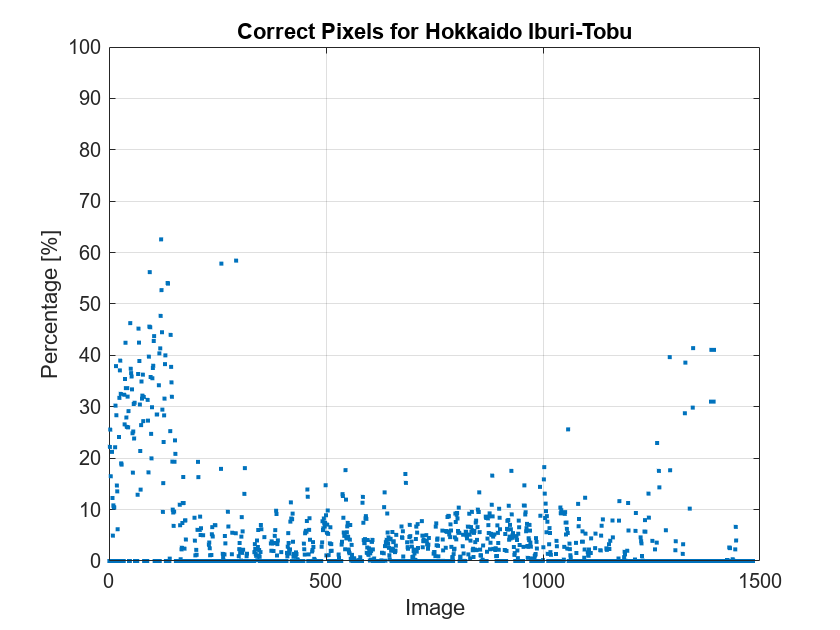

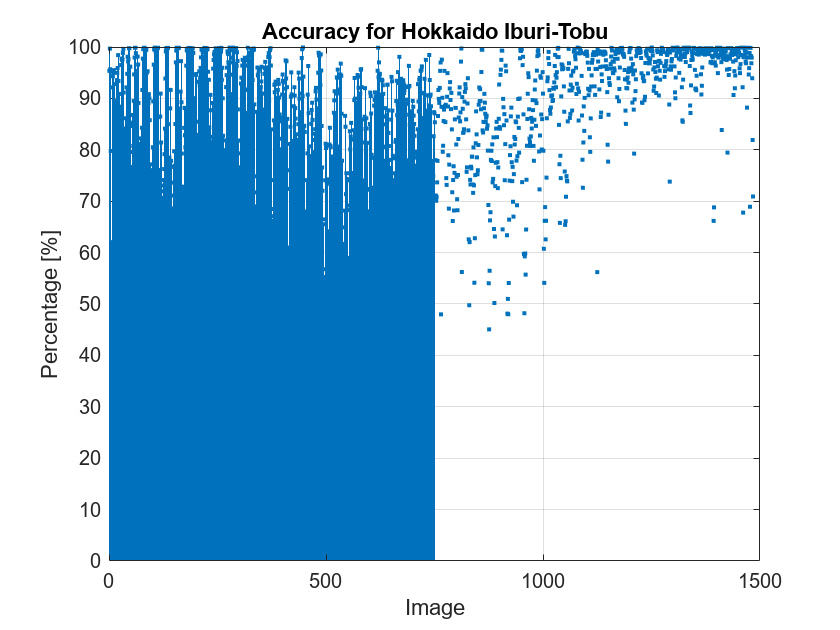

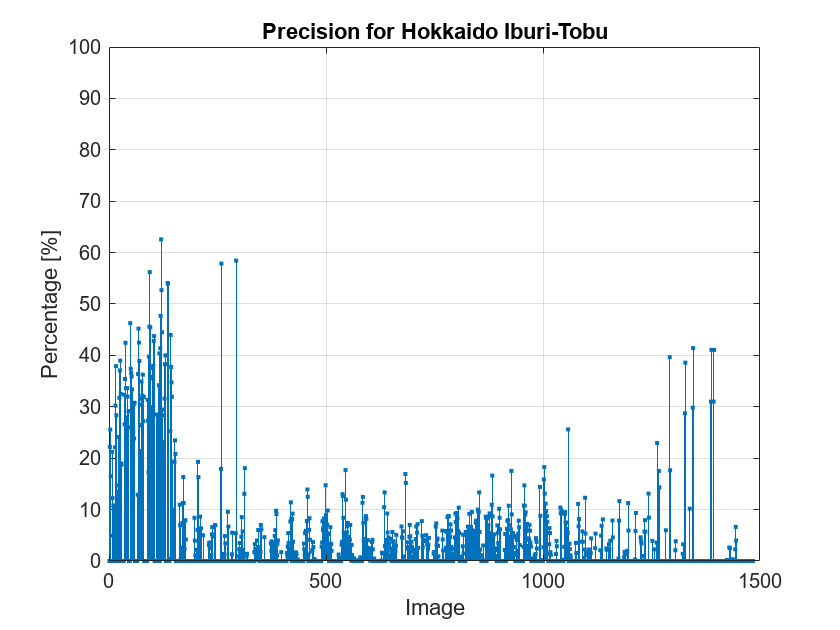

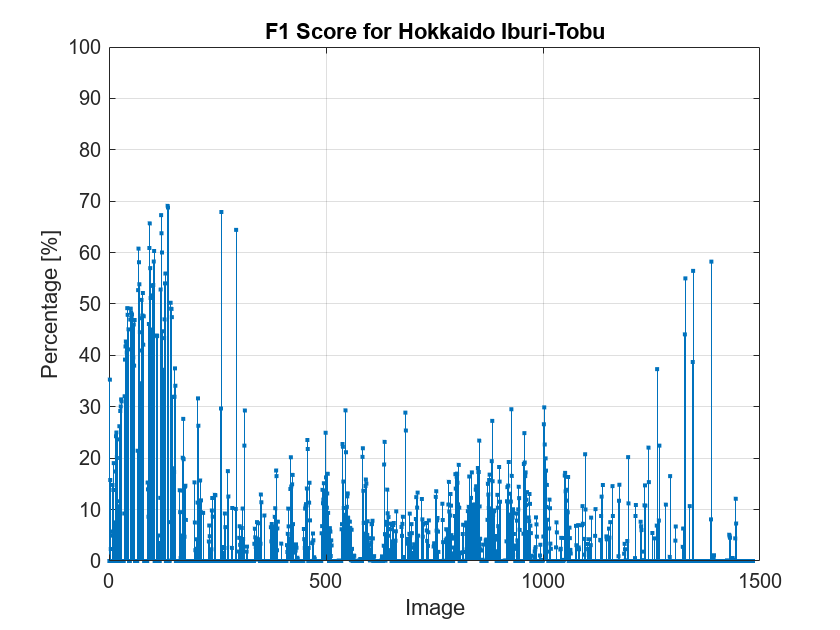


% Loop through each folder to compute stats
for i=1:numel(folders)
    list_imgs = dir(fullfile(orig_dir, folders{i}, 'img', '*.tif')); % Get images
    list_lbls = dir(fullfile(orig_dir, folders{i}, 'label', '*.tif')); % Get images
    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else
        % Create folder to output masks
        if ~exist(fullfile(output_dir,'Plots'), 'dir')
            mkdir(output_dir,'Plots');
        end
        %fprintf("For %s ||| Stats:\n", folders{i});

        % Calc stats per set
        correct_landslide_per_set{i} = mean((correct_landslide{i}));
        precision_per_set{i} = mean((precision{i}));
        recall_per_set{i} = mean((recall{i}));
        f1_score_per_set{i} = mean((f1_score{i}));
        accuracy_per_set{i} = mean((accuracy{i}));
        
        % Plot statistics
        figure;
        stem(correct_landslide{i}(:),'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Correct Pixels for %s", folders{i}));
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Correct_Landslide_%s.png',folders{i}));
        saveas(gcf, output_file); % Save current figure
        close(gcf); % Close figure to avoid memory usage
        figure;
        stem(accuracy{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Accuracy for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Accuracy_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(precision{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Precision for %s", folders{i}))
        grid on;
        ylim([0 100]);
        output_file = fullfile(output_dir,'Plots',sprintf('Precision_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(recall{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Recall for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Recall_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(f1_score{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("F1 Score for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('F1_Score_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(correct_landslide_per_set{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title("Correct Pixels per set");
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','Correct_Landslide.png');
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(accuracy_per_set{i}(:)*100,'.');
        xlabel('Set');
        ylabel('Percentage [%]');
        title("Accuracy per Set")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','Accuracy.png');
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(precision_per_set{i}(:)*100,'.');
        xlabel('Set');
        ylabel('Percentage [%]');
        title("Precision per Set")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','Precision.png');
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(recall_per_set{i}(:)*100,'.');
        xlabel('Set');
        ylabel('Percentage [%]');
        title("Recall per Set")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','Recall.png');
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(f1_score_per_set{i}(:)*100,'.');
        xlabel('Set');
        ylabel('Percentage [%]');
        title("F1 Score per Set")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','F1_Score.png');
        saveas(gcf, output_file);
        close(gcf); 

        % Calc stats per set
        local_precision_per_set{i} = mean((local_precision{i}));
        local_recall_per_set{i} = mean((local_recall{i}));
        local_f1_score_per_set{i} = mean((local_f1_score{i}));
        local_accuracy_per_set{i} = mean((local_accuracy{i}));
        
        % Plot statistics
        figure;
        stem(local_accuracy{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Accuracy for %s (Landslide Pixels)", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Accuracy_Pix_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(local_precision{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Precision for %s (Landslide Pixels)", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Precision_Pix_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(local_recall{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Recall for %s (Landslide Pixels)", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Recall_Pix_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(local_f1_score{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("F1 Score for %s (Landslide Pixels)", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('F1_Score_Pix_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(local_accuracy_per_set{i}(:)*100,'.');
        xlabel('Set');
        ylabel('Percentage [%]');
        title("Accuracy per Set (Landslide Pixels)")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','Accuracy_Pix.png');
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(local_precision_per_set{i}(:)*100,'.');
        xlabel('Set');
        ylabel('Percentage [%]');
        title("Precision per Set (Landslide Pixels)")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','Precision_Pix.png');
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(local_recall_per_set{i}(:)*100,'.');
        xlabel('Set');
        ylabel('Percentage [%]');
        title("Recall per Set (Landslide Pixels)")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','Recall_Pix.png');
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(local_f1_score_per_set{i}(:)*100,'.');
        xlabel('Set');
        ylabel('Percentage [%]');
        title("F1 Score per Set (Landslide Pixels)")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','F1_Score_Pix.png');
        saveas(gcf, output_file);
        close(gcf); 
    end
end



overall_correct_landslide_sp_cas = mean(cell2mat(correct_landslide_per_set))

overall_correct_landslide_sp_cas = 15.7118

overall_precision_sp_cas = mean(cell2mat(precision_per_set))

overall_precision_sp_cas = 0.1571

overall_pix_precision_sp_cas = mean(cell2mat(local_precision_per_set))

overall_pix_precision_sp_cas = 0.1571

overall_recall_sp_cas = mean(cell2mat(recall_per_set))

overall_recall_sp_cas = 0.3193

overall_pix_recall_sp_cas = mean(cell2mat(local_recall_per_set))

overall_pix_recall_sp_cas = 0.3193

overall_f1_score_sp_cas = mean(cell2mat(f1_score_per_set))

overall_f1_score_sp_cas = 0.1569

overall_pix_f1_score_sp_cas = mean(cell2mat(local_f1_score_per_set))

overall_pix_f1_score_sp_cas = 0.1569

overall_accuracy_sp_cas = mean(cell2mat(accuracy_per_set))

overall_accuracy_sp_cas = 0.8685

overall_pix_accuracy_sp_cas = mean(cell2mat(local_accuracy_per_set))

overall_pix_accuracy_sp_cas = 0.8685

% Open file
output_stats_id = fopen(output_stats_dir, 'a');
% Write seperator line
fprintf(output_stats_id, '----- Superpixel CAS 5 Closing -----\n'); 
% Log data
fprintf(output_stats_id, 'overall_correct_landslide_sp_cas = %.5f\n', overall_correct_landslide_sp_cas);
fprintf(output_stats_id, 'overall_precision_sp_cas = %.5f\n', overall_precision_sp_cas);
fprintf(output_stats_id, 'overall_pix_precision_sp_cas = %.5f\n', overall_pix_precision_sp_cas);
fprintf(output_stats_id, 'overall_recall_sp_cas = %.5f\n', overall_recall_sp_cas);
fprintf(output_stats_id, 'overall_pix_recall_sp_cas = %.5f\n', overall_pix_recall_sp_cas);
fprintf(output_stats_id, 'overall_f1_score_sp_cas = %.5f\n', overall_f1_score_sp_cas);
fprintf(output_stats_id, 'overall_pix_f1_score_sp_cas = %.5f\n', overall_pix_f1_score_sp_cas);
fprintf(output_stats_id, 'overall_accuracy_sp_cas = %.5f\n', overall_accuracy_sp_cas);
fprintf(output_stats_id, 'overall_pix_accuracy_sp_cas = %.5f\n', overall_pix_accuracy_sp_cas);
arr_correct_landslide_per_set = cell2mat(correct_landslide_per_set');

arr_correct_landslide_per_set =     4.3496   20.6766   16.5071    2.6469    6.8439   32.6897   18.7956   15.8866   28.6109   11.9724   12.1993   39.0710    8.7322    0.9832


arr_precision_per_set =     0.0435    0.2068    0.1651    0.0265    0.0684    0.3269    0.1880    0.1589    0.2861    0.1197    0.1220    0.3907    0.0873    0.0098


arr_local_precision_per_set =     0.0435    0.2068    0.1651    0.0265    0.0684    0.3269    0.1880    0.1589    0.2861    0.1197    0.1220    0.3907    0.0873    0.0098


arr_recall_per_set =     0.3003    0.6412    0.5163    0.0539    0.3799    0.5070    0.2993    0.1272    0.1960    0.2148    0.1580    0.4959    0.5562    0.0247


arr_local_recall_per_set =     0.3003    0.6412    0.5163    0.0539    0.3799    0.5070    0.2993    0.1272    0.1960    0.2148    0.1580    0.4959    0.5562    0.0247


arr_f1_score_per_set =     0.0609    0.2545    0.1933    0.0220    0.0909    0.3314    0.1825    0.1232    0.1884    0.1162    0.1097    0.3806    0.1342    0.0089


arr_local_f1_score_per_set =     0.0609    0.2545    0.1933    0.0220    0.0909    0.3314    0.1825    0.1232    0.1884    0.1162    0.1097    0.3806    0.1342    0.0089


arr_accuracy_per_set =     0.8849    0.7953    0.8530    0.9058    0.9024    0.8844    0.7938    0.8175    0.8582    0.8380    0.8430    0.8979    0.9573    0.9272


arr_local_accuracy_per_set =     0.8849    0.7953    0.8530    0.9058    0.9024    0.8844    0.7938    0.8175    0.8582    0.8380    0.8430    0.8979    0.9573    0.9272


fprintf(output_stats_id, 'Correct landslide per set: ');
fprintf(output_stats_id, '%.5f, ', arr_correct_landslide_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_correct_landslide_per_set(end));
arr_precision_per_set = cell2mat(precision_per_set);
fprintf(output_stats_id, 'Precision per set: ');
fprintf(output_stats_id, '%.5f, ', arr_precision_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_precision_per_set(end));
arr_local_precision_per_set = cell2mat(local_precision_per_set);
fprintf(output_stats_id, 'Local precision per set: ');
fprintf(output_stats_id, '%.5f, ', arr_local_precision_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_local_precision_per_set(end));
arr_recall_per_set = cell2mat(recall_per_set);
fprintf(output_stats_id, 'Recall per set: ');
fprintf(output_stats_id, '%.5f, ', arr_recall_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_recall_per_set(end));
arr_local_recall_per_set = cell2mat(local_recall_per_set)
fprintf(output_stats_id, 'Local recall per set: ');
fprintf(output_stats_id, '%.5f, ', arr_local_recall_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_local_recall_per_set(end));
arr_f1_score_per_set = cell2mat(f1_score_per_set);
fprintf(output_stats_id, 'F1 score per set: ');
fprintf(output_stats_id, '%.5f, ', arr_f1_score_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_f1_score_per_set(end));
arr_local_f1_score_per_set = cell2mat(local_f1_score_per_set);
fprintf(output_stats_id, 'Local F1 score per set: ');
fprintf(output_stats_id, '%.5f, ', arr_local_f1_score_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_local_f1_score_per_set(end));
arr_accuracy_per_set = cell2mat(accuracy_per_set);
fprintf(output_stats_id, 'Accuracy score per set: ');
fprintf(output_stats_id, '%.5f, ', arr_accuracy_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_accuracy_per_set(end));
arr_local_accuracy_per_set = cell2mat(local_accuracy_per_set);
fprintf(output_stats_id, 'Local accuracy score per set: ');
fprintf(output_stats_id, '%.5f, ', arr_local_accuracy_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_local_accuracy_per_set(end));
fprintf(output_stats_id, 'Duration of processing: %.1fs\n', elapsedTime);
% Close file
fclose(output_stats_id);

% Clear workspace to save RAM
clear all

#### Sense Dataset

clc; clear; close all;

imgs_proc = 0;

% Directories
orig_dir = 'C:\Users\andre\Year5\EE581\Project\Datasets\archive\TrainData\';
output_dir = 'C:\Users\andre\Year5\EE581\Project\Datasets\Masks\SP_Sense_5_Close\';
output_stats_dir = 'C:\Users\andre\EE581-LandlideProj\src\classical_methods\More_Stats_classical_methods.txt';

% Get list of folders inside directory
folders = dir(orig_dir);
folders = {folders([folders.isdir]).name}; % Get only folder names
folders = folders(~ismember(folders, {'.', '..'})); % Remove

% Set up stats storage
% Assign zero array of its image count
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels
% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count');
else
    true_pos = zeros(1,numel(list_imgs));
    false_pos = zeros(1,numel(list_imgs));
    true_neg = zeros(1,numel(list_imgs));
    false_neg = zeros(1,numel(list_imgs));
    precision = zeros(1,numel(list_imgs));
    recall = zeros(1,numel(list_imgs));
    f1_score = zeros(1,numel(list_imgs));
    accuracy = zeros(1,numel(list_imgs));
    correct_landslide = zeros(1,numel(list_imgs));
        
    local_true_pos = zeros(1,numel(list_imgs));
    local_false_pos = zeros(1,numel(list_imgs));
    local_true_neg = zeros(1,numel(list_imgs));
    local_false_neg = zeros(1,numel(list_imgs));
    local_precision = zeros(1,numel(list_imgs));
    local_recall = zeros(1,numel(list_imgs));
    local_f1_score = zeros(1,numel(list_imgs));
    local_accuracy = zeros(1,numel(list_imgs));
end

% Go through through folder
t1 = datetime('now');
% Get list of image and label files
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels

% Create folder for all outputs
if ~exist(output_dir,'dir')
    mkdir(output_dir); % Create folder if doesn't exist
end

% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count for folder: %s', folders{i});
else
    % Iterate through each image (and label) of each folder
    t2 = datetime('now');

    % Create folder to output masks
    if ~exist(fullfile(output_dir,'Mask'),'dir')
        mkdir(output_dir,'Mask'); % Create folder if doesn't exist
    end

    for k = 1:numel(list_imgs)
        imgs_proc = imgs_proc + 1;
        % Full path
        img_path = fullfile(orig_dir, folders{1}, list_imgs(k).name);
        lbl_path = fullfile(orig_dir, folders{2}, list_lbls(k).name);

        % Read HDF5 data
        img_info = h5info(img_path);
        img_name = img_info.Datasets(1).Name;
        img_chs = h5read(img_path, ['/' img_name]);
            
        label_info = h5info(lbl_path);
        label_name = label_info.Datasets(1).Name;
        label = h5read(lbl_path, ['/' label_name]);

        % Binarise image
        label = label > 0;

        % Extract channels
        R_CH = squeeze(img_chs(4,:,:));
        G_CH = squeeze(img_chs(3,:,:));
        B_CH = squeeze(img_chs(2,:,:));

        % Combine into an RGB image & label
        img = double(cat(3, R_CH, G_CH, B_CH));
        
        % Normalize images
        if max(img(:)) > 1
            img = img / max(img(:)); % Scale to [0, 1]
        end
        
        % Calculate superpixels of the image.
        [L,N] = superpixels(img,500);
        output_image = zeros(size(img),'like',img);
        idx = label2idx(L);
        num_rows = size(img,1);
        num_cols = size(img,2);
        for label_val = 1:N
            red_idx = idx{label_val};
            green_idx = idx{label_val}+num_rows*num_cols;
            blue_idx = idx{label_val}+2*num_rows*num_cols;
            output_image(red_idx) = mean(img(red_idx));
            output_image(green_idx) = mean(img(green_idx));
            output_image(blue_idx) = mean(img(blue_idx));
        end
        mask = im2gray(output_image);
        mask = (mask > 0.8);
        mask = imclose(mask, strel('disk', 5)); % Fill gaps
        
        % Statistcally analyse results
        true_pos(k) = sum(label & mask, 'all');
        false_pos(k) = sum(label & ~mask, 'all');
        true_neg(k) = sum(~label & ~mask, 'all');
        false_neg(k) = sum(~label & mask, 'all');
        accuracy(k) = (true_pos(k) + true_neg(k)) / (true_pos(k) + true_neg(k) + false_pos(k) + false_neg(k));
        if (true_pos(k) + false_pos(k)) == 0
            precision(k) = 0;
        else
            precision(k) = true_pos(k) / (true_pos(k) + false_pos(k));
        end
        if (true_pos(k) + false_neg(k)) == 0
            recall(k) = 0;
        else
            recall(k) = true_pos(k) / (true_pos(k) + false_neg(k));
        end
        if (precision(k) + recall(k)) == 0
            f1_score(k) = 0;
        else
            f1_score(k) = (2 * precision(k) * recall(k)) / (precision(k) + recall(k));
        end

        % Statistcally analyse results
        labelled_pixs = (label == 1); % Logical mask of landslide locations
        % Compare mask w/ label directly
        local_true_pos(k) = sum(labelled_pixs & (mask == 1), 'all'); % Landlside in label & mask
        local_false_pos(k) = sum(labelled_pixs & (mask == 0), 'all'); % Landlside in label & mask
        local_true_neg(k) = sum(~labelled_pixs & (mask == 0), 'all'); % Landlside in label & mask
        local_false_neg(k) = sum(~labelled_pixs & (mask == 1), 'all'); % Landlside in label & mask
        
        local_accuracy(k) = (local_true_pos(k) + local_true_neg(k)) / (local_true_pos(k) + local_true_neg(k) + local_false_pos(k) + local_false_neg(k));
        if (local_true_pos(k) + local_false_pos(k)) == 0
            local_precision(k) = 0;
        else
            local_precision(k) = local_true_pos(k) / (local_true_pos(k) + local_false_pos(k));
        end

        if (local_true_pos(k) + local_false_neg(k)) == 0
            local_recall(k) = 0;
        else
            local_recall(k) = local_true_pos(k) / (local_true_pos(k) + local_false_neg(k));
        end
        if (local_precision(k) + local_recall(k)) == 0
            local_f1_score(k) = 0;
        else
            local_f1_score(k) = (2 * local_precision(k) * local_recall(k)) / (local_precision(k) + local_recall(k));
        end

        % Locally
        %[x_lbl, y_lbl] = find(label); % Locations within labelled
        %correct_pix = mask(sub2ind(size(mask), x_lbl, y_lbl)) == 1; % Logical array to compare - correctly identified 
        %fprintf("For %s Result=%.1f\n", folders, local_true_pos(k)/sum(label(:))*100);    
        if sum(label(:)) == 0
            if local_true_pos(k) == 0
                correct_landslide(k) = 100; % ---
            else
                correct_landslide(k) = 0;
            end
        else
            correct_landslide(k) = local_true_pos(k)/sum(label(:))*100;
        end
        mask_name = split(list_imgs(k).name, '.');
        mask_name = [mask_name{1}, '.jpg'];
        output_file = fullfile(output_dir,'Mask',mask_name);
        imwrite(mask,output_file);
    end
end

t3 = datetime('now');
elapsedTime = seconds(t3-t1); % Cacluate elapsed times
fprintf("Total processing time: %.1fs", elapsedTime);    

Total processing time: 169.0s

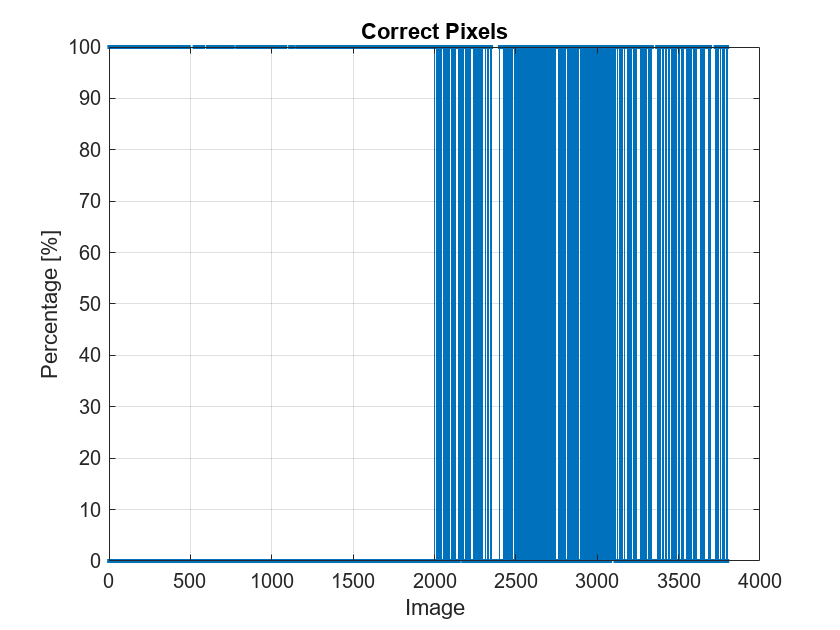

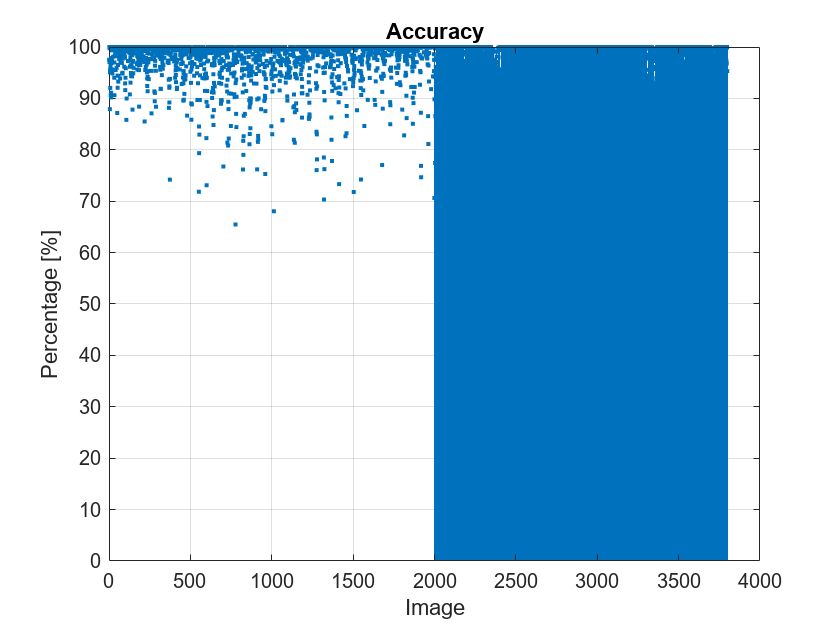

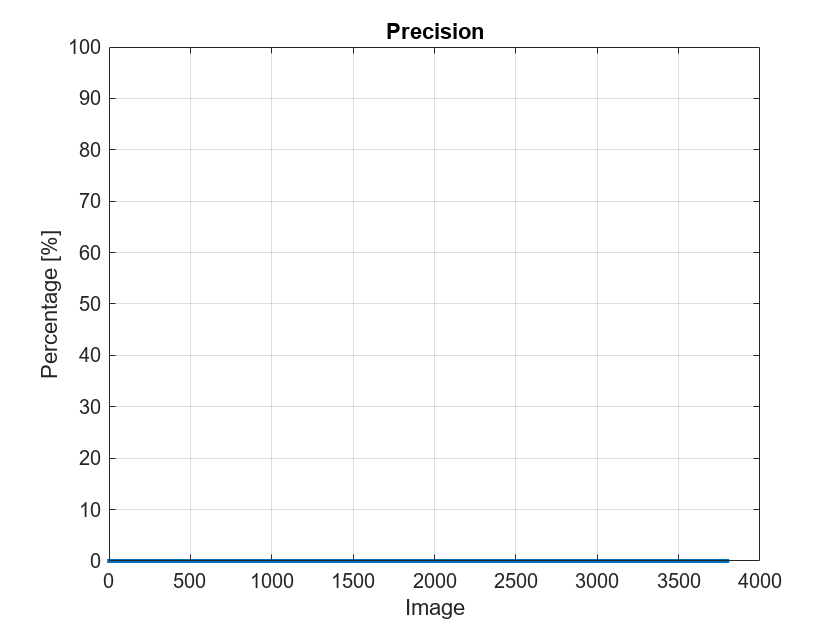

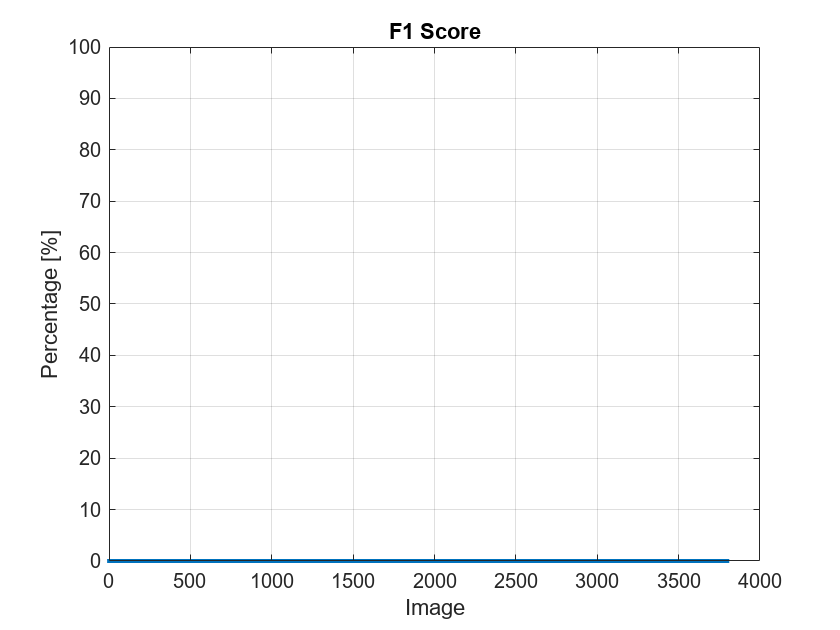


% Go through folder to compute stats
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels
% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count');
else

    % Create folder to output masks
    if ~exist(fullfile(output_dir,'Plots'), 'dir')
        mkdir(output_dir,'Plots');
    end

    % Plot statistics
    figure;
    stem(correct_landslide,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Correct Pixels");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Correct_Landslide.png');
    saveas(gcf, output_file); % Save current figure
    close(gcf); % Close figure to avoid memory usage
    figure;
    stem(accuracy*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Accuracy");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Accuracy.png');
    saveas(gcf, output_file);
    close(gcf); 
    figure;
    stem(precision*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Precision");
    grid on;
    ylim([0 100]);
    output_file = fullfile(output_dir,'Plots','Precision.png');
    saveas(gcf, output_file);
    close(gcf); 
    figure;
    stem(recall*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Recall");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Recall.png');
    saveas(gcf, output_file);
    close(gcf); 
    figure;
    stem(f1_score*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("F1 Score");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','F1_Score.png');
    saveas(gcf, output_file);
    close(gcf); 
    
    % Plot statistics
    figure;
    stem(local_accuracy*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Accuracy (Landslide Pixels)");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Accuracy_Pix.png');
    saveas(gcf, output_file);
    close(gcf);
    figure;
    stem(local_precision*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Precision (Landslide Pixels)");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Precision_Pix.png');
    saveas(gcf, output_file);
    close(gcf);
    figure;
    stem(local_recall*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Recall (Landslide Pixels)");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Recall_Pix.png');
    saveas(gcf, output_file);
    close(gcf);
    figure;
    stem(local_f1_score*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("F1 Score (Landslide Pixels)");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','F1_Score_Pix.png');
    saveas(gcf, output_file);
    close(gcf);
end


overall_correct_landslide_sp_sense_cas_no_closing = mean(correct_landslide)

overall_correct_landslide_sp_sense_cas_no_closing = 41.2740

overall_precision_sp_sense_cas_no_closing = mean(precision)

overall_precision_sp_sense_cas_no_closing = 0

overall_pix_precision_sp_sense_cas_no_closing = mean(local_precision)

overall_pix_precision_sp_sense_cas_no_closing = 0

overall_recall_sp_sense_cas_no_closing = mean(recall)

overall_recall_sp_sense_cas_no_closing = 0

overall_pix_recall_sp_sense_cas_no_closing = mean(local_recall)

overall_pix_recall_sp_sense_cas_no_closing = 0

overall_f1_score_sp_sense_cas_no_closing = mean(f1_score)

overall_f1_score_sp_sense_cas_no_closing = 0

overall_pix_f1_score_sp_sense_cas_no_closing = mean(local_f1_score)

overall_pix_f1_score_sp_sense_cas_no_closing = 0

overall_accuracy_sp_sense_cas_no_closing = mean(accuracy)

overall_accuracy_sp_sense_cas_no_closing = 0.9763

overall_pix_accuracy_sp_sense_cas_no_closing = mean(local_accuracy)

overall_pix_accuracy_sp_sense_cas_no_closing = 0.9763


% Open file
output_stats_id = fopen(output_stats_dir, 'a');
% Write seperator line
fprintf(output_stats_id, '----- Superpixel Sense 5 Closing -----\n'); 
% Log data
fprintf(output_stats_id, 'overall_correct_landslide_sp_sense_cas_no_closing = %.5f\n', overall_correct_landslide_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'overall_precision_sp_sense_cas_no_closing = %.5f\n', overall_precision_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'overall_pix_precision_sp_sense_cas_no_closing = %.5f\n', overall_pix_precision_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'overall_recall_sp_sense_cas_no_closing = %.5f\n', overall_recall_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'overall_pix_recall_sp_sense_cas_no_closing = %.5f\n', overall_pix_recall_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'overall_f1_score_sp_sense_cas_no_closing = %.5f\n', overall_f1_score_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'overall_pix_f1_score_sp_sense_cas_no_closing = %.5f\n', overall_pix_f1_score_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'overall_accuracy_sp_sense_cas_no_closing = %.5f\n', overall_accuracy_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'overall_pix_accuracy_sp_sense_cas_no_closing = %.5f\n', overall_pix_accuracy_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'Duration of processing: %.1fs\n', elapsedTime);
% Close file
fclose(output_stats_id);

end_time_sp_no_closing = datetime('now');
save('end_time_sp_no_closing.mat', 'end_time_sp_no_closing');

clear all;

### Superpixel - 7 Closing

#### CAS Dataset

clc; clear; close all;

imgs_proc = 0;

% Directories
orig_dir = 'C:\Users\andre\EE581-LandlideProj\data\original_dataset\';
output_dir = 'C:\Users\andre\Year5\EE581\Project\Datasets\Masks\SP_CAS_7_Close\';
output_stats_dir = 'C:\Users\andre\EE581-LandlideProj\src\classical_methods\More_Stats_classical_methods.txt';

% Get list of folders inside directory
folders = dir(orig_dir);
folders = {folders([folders.isdir]).name}; % Get only folder names
folders = folders(~ismember(folders, {'.', '..', ...
    'Longxi River(UAV)','Tiburon Peninsula(Sentinel)'})); % Remove

% Set up stats storage
true_pos = cell(numel(folders),1); % Cell array - folder per row
false_pos = cell(numel(folders),1);
true_neg = cell(numel(folders),1);
false_neg = cell(numel(folders),1);
precision = cell(numel(folders),1);
recall = cell(numel(folders),1);
f1_score = cell(numel(folders),1);
accuracy = cell(numel(folders),1);
precision_per_set = cell(1,numel(folders));
recall_per_set = cell(1,numel(folders));
f1_score_per_set = cell(1,numel(folders));
accuracy_per_set = cell(1,numel(folders));
correct_landslide = cell(numel(folders),1);
correct_landslide_per_set = cell(numel(folders),1);

local_true_pos = cell(numel(folders),1);
local_false_pos = cell(numel(folders),1);
local_true_neg = cell(numel(folders),1);
local_false_neg = cell(numel(folders),1);
local_precision = cell(numel(folders),1);
local_recall = cell(numel(folders),1);
local_f1_score = cell(numel(folders),1);
local_accuracy = cell(numel(folders),1);
local_precision_per_set = cell(1,numel(folders));
local_recall_per_set = cell(1,numel(folders));
local_f1_score_per_set = cell(1,numel(folders));
local_accuracy_per_set = cell(1,numel(folders));

% Loop through each folder & assign zero array of its image count
for i=1:numel(folders)
    list_imgs = dir(fullfile(orig_dir, folders{i}, 'img', '*.tif')); % Get images
    list_lbls = dir(fullfile(orig_dir, folders{i}, 'label', '*.tif')); % Get images
    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else
        true_pos{i} = zeros(1,numel(list_imgs)); % Each cell contains image count
        false_pos{i} = zeros(1,numel(list_imgs));
        true_neg{i} = zeros(1,numel(list_imgs));
        false_neg{i} = zeros(1,numel(list_imgs));
        precision{i} = zeros(1,numel(list_imgs));
        recall{i} = zeros(1,numel(list_imgs));
        f1_score{i} = zeros(1,numel(list_imgs));
        accuracy{i} = zeros(1,numel(list_imgs));
        correct_landslide{i} = zeros(1,numel(list_imgs));
        
        local_true_pos{i} = zeros(1,numel(list_imgs));
        local_false_pos{i} = zeros(1,numel(list_imgs));
        local_true_neg{i} = zeros(1,numel(list_imgs));
        local_false_neg{i} = zeros(1,numel(list_imgs));
        local_precision{i} = zeros(1,numel(list_imgs));
        local_recall{i} = zeros(1,numel(list_imgs));
        local_f1_score{i} = zeros(1,numel(list_imgs));
        local_accuracy{i} = zeros(1,numel(list_imgs));
    end
end

% Iterate through each folder
t1 = datetime('now');
for i=1:numel(folders)
    % Directory
    img_dir = fullfile(orig_dir, folders{i}, 'img');
    lbl_dir = fullfile(orig_dir, folders{i}, 'label');

    % Get list of image and label files
    list_imgs = dir(fullfile(img_dir, '*.tif'));
    list_lbls = dir(fullfile(lbl_dir, '*.tif'));
    
    % Create folder to output masks
    if ~exist(fullfile(output_dir,folders{i}), 'dir')
        mkdir(output_dir,folders{i}); % Create folder if doesn't exist
    end

    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else

        % Iterate through each image (and label) of each folder
        t2 = datetime('now');
        for k = 1:numel(list_imgs)
            imgs_proc = imgs_proc + 1;
            % Directory
            img_path = fullfile(img_dir, list_imgs(k).name);
            lbl_path = fullfile(lbl_dir, list_lbls(k).name);
    
            % Load data and label
            img = double(imread(img_path));
            label = double(imread(lbl_path));
    
            % Normalize images
            if max(img(:)) > 1
                img = img / max(img(:)); % Scale to [0, 1]
            end
            if max(label(:)) > 1
                label = label / max(label(:)); % Scale to [0, 1]
            end

            % Binarise the label and invert it so landslied is 1
            
            label_temp = label;
            label_temp(label_temp == 255) = 1;
            label_bin = (label_temp(:,:,1) + label_temp(:,:,2) + label_temp(:,:,3)) > 0;
            label = 1 - label_bin;    
            
            % Calculate superpixels of the image.
            [L,N] = superpixels(img,500);
            output_image = zeros(size(img),'like',img);
            idx = label2idx(L);
            num_rows = size(img,1);
            num_cols = size(img,2);
            for label_val = 1:N
                red_idx = idx{label_val};
                green_idx = idx{label_val}+num_rows*num_cols;
                blue_idx = idx{label_val}+2*num_rows*num_cols;
                output_image(red_idx) = mean(img(red_idx));
                output_image(green_idx) = mean(img(green_idx));
                output_image(blue_idx) = mean(img(blue_idx));
            end    
            mask = im2gray(output_image);
            mask = (mask > 0.8);
            mask = imclose(mask, strel('disk', 7)); % Fill gaps

            % Statistcally analyse results
            true_pos{i}(k) = sum(label & mask, 'all');
            false_pos{i}(k) = sum(label & ~mask, 'all');
            true_neg{i}(k) = sum(~label & ~mask, 'all');
            false_neg{i}(k) = sum(~label & mask, 'all');
            accuracy{i}(k) = (true_pos{i}(k) + true_neg{i}(k)) / (true_pos{i}(k) + true_neg{i}(k) + false_pos{i}(k) + false_neg{i}(k));
            if (true_pos{i}(k) + false_pos{i}(k)) == 0
                precision{i}(k) = 0;
            else
                precision{i}(k) = true_pos{i}(k) / (true_pos{i}(k) + false_pos{i}(k));
            end
            if (true_pos{i}(k) + false_neg{i}(k)) == 0
                recall{i}(k) = 0;
            else
                recall{i}(k) = true_pos{i}(k) / (true_pos{i}(k) + false_neg{i}(k));
            end
            if (precision{i}(k) + recall{i}(k)) == 0
                f1_score{i}(k) = 0;
            else
                f1_score{i}(k) = (2 * precision{i}(k) * recall{i}(k)) / (precision{i}(k) + recall{i}(k));
            end

            % Statistcally analyse results
            labelled_pixs = (label == 1); % Logical mask of landslide locations
            % Compare mask w/ label directly
            local_true_pos{i}(k) = sum(labelled_pixs & (mask == 1), 'all'); % Landlside in label & mask
            local_false_pos{i}(k) = sum(labelled_pixs & (mask == 0), 'all'); % Landlside in label & mask
            local_true_neg{i}(k) = sum(~labelled_pixs & (mask == 0), 'all'); % Landlside in label & mask
            local_false_neg{i}(k) = sum(~labelled_pixs & (mask == 1), 'all'); % Landlside in label & mask
            
            local_accuracy{i}(k) = (local_true_pos{i}(k) + local_true_neg{i}(k)) / (local_true_pos{i}(k) + local_true_neg{i}(k) + local_false_pos{i}(k) + local_false_neg{i}(k));
            if (local_true_pos{i}(k) + local_false_pos{i}(k)) == 0
                local_precision{i}(k) = 0;
            else
                local_precision{i}(k) = local_true_pos{i}(k) / (local_true_pos{i}(k) + local_false_pos{i}(k));
            end
            if (local_true_pos{i}(k) + local_false_neg{i}(k)) == 0
                local_recall{i}(k) = 0;
            else
                local_recall{i}(k) = local_true_pos{i}(k) / (local_true_pos{i}(k) + local_false_neg{i}(k));
            end
            if (local_precision{i}(k) + local_recall{i}(k)) == 0
                local_f1_score{i}(k) = 0;
            else
                local_f1_score{i}(k) = (2 * local_precision{i}(k) * local_recall{i}(k)) / (local_precision{i}(k) + local_recall{i}(k));
            end
            
            % Locally
            %[x_lbl, y_lbl] = find(label); % Locations within labelled
            %correct_pix = mask(sub2ind(size(mask), x_lbl, y_lbl)) == 1; % Logical array to compare - correctly identified 
            %fprintf("For %s Result=%.1f\n", folders{i}, local_true_pos{i}(k)/sum(label(:))*100);    
            correct_landslide{i}(k) = local_true_pos{i}(k)/sum(label(:))*100;
            output_file = fullfile(output_dir,folders{i},list_imgs(k).name);
            imwrite(mask,output_file);
        end
    end
    t3 = datetime('now');
    elapsedTime = seconds(t3-t2); % Cacluate elapsed times
    fprintf("%s --- Took %.1fs\n", folders{i} , elapsedTime);    
end
t3 = datetime('now');
elapsedTime = seconds(t3-t1); % Cacluate elapsed times
fprintf("Total processing time: %.1fs", elapsedTime);    

% Loop through each folder to compute stats
for i=1:numel(folders)
    list_imgs = dir(fullfile(orig_dir, folders{i}, 'img', '*.tif')); % Get images
    list_lbls = dir(fullfile(orig_dir, folders{i}, 'label', '*.tif')); % Get images
    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else
        % Create folder to output masks
        if ~exist(fullfile(output_dir,'Plots'), 'dir')
            mkdir(output_dir,'Plots');
        end
        %fprintf("For %s ||| Stats:\n", folders{i});

        % Calc stats per set
        correct_landslide_per_set{i} = mean((correct_landslide{i}));
        precision_per_set{i} = mean((precision{i}));
        recall_per_set{i} = mean((recall{i}));
        f1_score_per_set{i} = mean((f1_score{i}));
        accuracy_per_set{i} = mean((accuracy{i}));
        
        % Plot statistics
        figure;
        stem(correct_landslide{i}(:),'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Correct Pixels for %s", folders{i}));
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Correct_Landslide_%s.png',folders{i}));
        saveas(gcf, output_file); % Save current figure
        close(gcf); % Close figure to avoid memory usage
        figure;
        stem(accuracy{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Accuracy for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Accuracy_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(precision{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Precision for %s", folders{i}))
        grid on;
        ylim([0 100]);
        output_file = fullfile(output_dir,'Plots',sprintf('Precision_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(recall{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Recall for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Recall_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(f1_score{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("F1 Score for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('F1_Score_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(correct_landslide_per_set{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title("Correct Pixels per set");
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','Correct_Landslide.png');
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(accuracy_per_set{i}(:)*100,'.');
        xlabel('Set');
        ylabel('Percentage [%]');
        title("Accuracy per Set")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','Accuracy.png');
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(precision_per_set{i}(:)*100,'.');
        xlabel('Set');
        ylabel('Percentage [%]');
        title("Precision per Set")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','Precision.png');
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(recall_per_set{i}(:)*100,'.');
        xlabel('Set');
        ylabel('Percentage [%]');
        title("Recall per Set")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','Recall.png');
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(f1_score_per_set{i}(:)*100,'.');
        xlabel('Set');
        ylabel('Percentage [%]');
        title("F1 Score per Set")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','F1_Score.png');
        saveas(gcf, output_file);
        close(gcf); 

        % Calc stats per set
        local_precision_per_set{i} = mean((local_precision{i}));
        local_recall_per_set{i} = mean((local_recall{i}));
        local_f1_score_per_set{i} = mean((local_f1_score{i}));
        local_accuracy_per_set{i} = mean((local_accuracy{i}));
        
        % Plot statistics
        figure;
        stem(local_accuracy{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Accuracy for %s (Landslide Pixels)", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Accuracy_Pix_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(local_precision{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Precision for %s (Landslide Pixels)", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Precision_Pix_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(local_recall{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Recall for %s (Landslide Pixels)", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Recall_Pix_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(local_f1_score{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("F1 Score for %s (Landslide Pixels)", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('F1_Score_Pix_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(local_accuracy_per_set{i}(:)*100,'.');
        xlabel('Set');
        ylabel('Percentage [%]');
        title("Accuracy per Set (Landslide Pixels)")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','Accuracy_Pix.png');
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(local_precision_per_set{i}(:)*100,'.');
        xlabel('Set');
        ylabel('Percentage [%]');
        title("Precision per Set (Landslide Pixels)")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','Precision_Pix.png');
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(local_recall_per_set{i}(:)*100,'.');
        xlabel('Set');
        ylabel('Percentage [%]');
        title("Recall per Set (Landslide Pixels)")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','Recall_Pix.png');
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(local_f1_score_per_set{i}(:)*100,'.');
        xlabel('Set');
        ylabel('Percentage [%]');
        title("F1 Score per Set (Landslide Pixels)")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','F1_Score_Pix.png');
        saveas(gcf, output_file);
        close(gcf); 
    end
end


overall_correct_landslide_sp_cas = mean(cell2mat(correct_landslide_per_set))
overall_precision_sp_cas = mean(cell2mat(precision_per_set))
overall_pix_precision_sp_cas = mean(cell2mat(local_precision_per_set))
overall_recall_sp_cas = mean(cell2mat(recall_per_set))
overall_pix_recall_sp_cas = mean(cell2mat(local_recall_per_set))
overall_f1_score_sp_cas = mean(cell2mat(f1_score_per_set))
overall_pix_f1_score_sp_cas = mean(cell2mat(local_f1_score_per_set))
overall_accuracy_sp_cas = mean(cell2mat(accuracy_per_set))
overall_pix_accuracy_sp_cas = mean(cell2mat(local_accuracy_per_set))
% Open file
output_stats_id = fopen(output_stats_dir, 'a');
% Write seperator line
fprintf(output_stats_id, '----- Superpixel CAS 7 Closing -----\n'); 
% Log data
fprintf(output_stats_id, 'overall_correct_landslide_sp_cas = %.5f\n', overall_correct_landslide_sp_cas);
fprintf(output_stats_id, 'overall_precision_sp_cas = %.5f\n', overall_precision_sp_cas);
fprintf(output_stats_id, 'overall_pix_precision_sp_cas = %.5f\n', overall_pix_precision_sp_cas);
fprintf(output_stats_id, 'overall_recall_sp_cas = %.5f\n', overall_recall_sp_cas);
fprintf(output_stats_id, 'overall_pix_recall_sp_cas = %.5f\n', overall_pix_recall_sp_cas);
fprintf(output_stats_id, 'overall_f1_score_sp_cas = %.5f\n', overall_f1_score_sp_cas);
fprintf(output_stats_id, 'overall_pix_f1_score_sp_cas = %.5f\n', overall_pix_f1_score_sp_cas);
fprintf(output_stats_id, 'overall_accuracy_sp_cas = %.5f\n', overall_accuracy_sp_cas);
fprintf(output_stats_id, 'overall_pix_accuracy_sp_cas = %.5f\n', overall_pix_accuracy_sp_cas);
arr_correct_landslide_per_set = cell2mat(correct_landslide_per_set');
fprintf(output_stats_id, 'Correct landslide per set: ');
fprintf(output_stats_id, '%.5f, ', arr_correct_landslide_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_correct_landslide_per_set(end));
arr_precision_per_set = cell2mat(precision_per_set);
fprintf(output_stats_id, 'Precision per set: ');
fprintf(output_stats_id, '%.5f, ', arr_precision_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_precision_per_set(end));
arr_local_precision_per_set = cell2mat(local_precision_per_set);
fprintf(output_stats_id, 'Local precision per set: ');
fprintf(output_stats_id, '%.5f, ', arr_local_precision_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_local_precision_per_set(end));
arr_recall_per_set = cell2mat(recall_per_set);
fprintf(output_stats_id, 'Recall per set: ');
fprintf(output_stats_id, '%.5f, ', arr_recall_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_recall_per_set(end));
arr_local_recall_per_set = cell2mat(local_recall_per_set)
fprintf(output_stats_id, 'Local recall per set: ');
fprintf(output_stats_id, '%.5f, ', arr_local_recall_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_local_recall_per_set(end));
arr_f1_score_per_set = cell2mat(f1_score_per_set);
fprintf(output_stats_id, 'F1 score per set: ');
fprintf(output_stats_id, '%.5f, ', arr_f1_score_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_f1_score_per_set(end));
arr_local_f1_score_per_set = cell2mat(local_f1_score_per_set);
fprintf(output_stats_id, 'Local F1 score per set: ');
fprintf(output_stats_id, '%.5f, ', arr_local_f1_score_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_local_f1_score_per_set(end));
arr_accuracy_per_set = cell2mat(accuracy_per_set);
fprintf(output_stats_id, 'Accuracy score per set: ');
fprintf(output_stats_id, '%.5f, ', arr_accuracy_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_accuracy_per_set(end));
arr_local_accuracy_per_set = cell2mat(local_accuracy_per_set);
fprintf(output_stats_id, 'Local accuracy score per set: ');
fprintf(output_stats_id, '%.5f, ', arr_local_accuracy_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_local_accuracy_per_set(end));
fprintf(output_stats_id, 'Duration of processing: %.1fs\n', elapsedTime);
% Close file
fclose(output_stats_id);

% Clear workspace to save RAM
clear all

#### Sense Dataset

clc; clear; close all;

imgs_proc = 0;

% Directories
orig_dir = 'C:\Users\andre\Year5\EE581\Project\Datasets\archive\TrainData\';
output_dir = 'C:\Users\andre\Year5\EE581\Project\Datasets\Masks\SP_Sense_7_Close\';
output_stats_dir = 'C:\Users\andre\EE581-LandlideProj\src\classical_methods\More_Stats_classical_methods.txt';

% Get list of folders inside directory
folders = dir(orig_dir);
folders = {folders([folders.isdir]).name}; % Get only folder names
folders = folders(~ismember(folders, {'.', '..'})); % Remove

% Set up stats storage
% Assign zero array of its image count
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels
% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count');
else
    true_pos = zeros(1,numel(list_imgs));
    false_pos = zeros(1,numel(list_imgs));
    true_neg = zeros(1,numel(list_imgs));
    false_neg = zeros(1,numel(list_imgs));
    precision = zeros(1,numel(list_imgs));
    recall = zeros(1,numel(list_imgs));
    f1_score = zeros(1,numel(list_imgs));
    accuracy = zeros(1,numel(list_imgs));
    correct_landslide = zeros(1,numel(list_imgs));
        
    local_true_pos = zeros(1,numel(list_imgs));
    local_false_pos = zeros(1,numel(list_imgs));
    local_true_neg = zeros(1,numel(list_imgs));
    local_false_neg = zeros(1,numel(list_imgs));
    local_precision = zeros(1,numel(list_imgs));
    local_recall = zeros(1,numel(list_imgs));
    local_f1_score = zeros(1,numel(list_imgs));
    local_accuracy = zeros(1,numel(list_imgs));
end

% Go through through folder
t1 = datetime('now');
% Get list of image and label files
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels

% Create folder for all outputs
if ~exist(output_dir,'dir')
    mkdir(output_dir); % Create folder if doesn't exist
end

% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count for folder: %s', folders{i});
else
    % Iterate through each image (and label) of each folder
    t2 = datetime('now');

    % Create folder to output masks
    if ~exist(fullfile(output_dir,'Mask'),'dir')
        mkdir(output_dir,'Mask'); % Create folder if doesn't exist
    end

    for k = 1:numel(list_imgs)
        imgs_proc = imgs_proc + 1;
        % Full path
        img_path = fullfile(orig_dir, folders{1}, list_imgs(k).name);
        lbl_path = fullfile(orig_dir, folders{2}, list_lbls(k).name);

        % Read HDF5 data
        img_info = h5info(img_path);
        img_name = img_info.Datasets(1).Name;
        img_chs = h5read(img_path, ['/' img_name]);
            
        label_info = h5info(lbl_path);
        label_name = label_info.Datasets(1).Name;
        label = h5read(lbl_path, ['/' label_name]);

        % Binarise image
        label = label > 0;

        % Extract channels
        R_CH = squeeze(img_chs(4,:,:));
        G_CH = squeeze(img_chs(3,:,:));
        B_CH = squeeze(img_chs(2,:,:));

        % Combine into an RGB image & label
        img = double(cat(3, R_CH, G_CH, B_CH));
        
        % Normalize images
        if max(img(:)) > 1
            img = img / max(img(:)); % Scale to [0, 1]
        end
        
        % Calculate superpixels of the image.
        [L,N] = superpixels(img,500);
        output_image = zeros(size(img),'like',img);
        idx = label2idx(L);
        num_rows = size(img,1);
        num_cols = size(img,2);
        for label_val = 1:N
            red_idx = idx{label_val};
            green_idx = idx{label_val}+num_rows*num_cols;
            blue_idx = idx{label_val}+2*num_rows*num_cols;
            output_image(red_idx) = mean(img(red_idx));
            output_image(green_idx) = mean(img(green_idx));
            output_image(blue_idx) = mean(img(blue_idx));
        end
        mask = im2gray(output_image);
        mask = (mask > 0.8);
        mask = imclose(mask, strel('disk', 7)); % Fill gaps
        
        % Statistcally analyse results
        true_pos(k) = sum(label & mask, 'all');
        false_pos(k) = sum(label & ~mask, 'all');
        true_neg(k) = sum(~label & ~mask, 'all');
        false_neg(k) = sum(~label & mask, 'all');
        accuracy(k) = (true_pos(k) + true_neg(k)) / (true_pos(k) + true_neg(k) + false_pos(k) + false_neg(k));
        if (true_pos(k) + false_pos(k)) == 0
            precision(k) = 0;
        else
            precision(k) = true_pos(k) / (true_pos(k) + false_pos(k));
        end
        if (true_pos(k) + false_neg(k)) == 0
            recall(k) = 0;
        else
            recall(k) = true_pos(k) / (true_pos(k) + false_neg(k));
        end
        if (precision(k) + recall(k)) == 0
            f1_score(k) = 0;
        else
            f1_score(k) = (2 * precision(k) * recall(k)) / (precision(k) + recall(k));
        end

        % Statistcally analyse results
        labelled_pixs = (label == 1); % Logical mask of landslide locations
        % Compare mask w/ label directly
        local_true_pos(k) = sum(labelled_pixs & (mask == 1), 'all'); % Landlside in label & mask
        local_false_pos(k) = sum(labelled_pixs & (mask == 0), 'all'); % Landlside in label & mask
        local_true_neg(k) = sum(~labelled_pixs & (mask == 0), 'all'); % Landlside in label & mask
        local_false_neg(k) = sum(~labelled_pixs & (mask == 1), 'all'); % Landlside in label & mask
        
        local_accuracy(k) = (local_true_pos(k) + local_true_neg(k)) / (local_true_pos(k) + local_true_neg(k) + local_false_pos(k) + local_false_neg(k));
        if (local_true_pos(k) + local_false_pos(k)) == 0
            local_precision(k) = 0;
        else
            local_precision(k) = local_true_pos(k) / (local_true_pos(k) + local_false_pos(k));
        end

        if (local_true_pos(k) + local_false_neg(k)) == 0
            local_recall(k) = 0;
        else
            local_recall(k) = local_true_pos(k) / (local_true_pos(k) + local_false_neg(k));
        end
        if (local_precision(k) + local_recall(k)) == 0
            local_f1_score(k) = 0;
        else
            local_f1_score(k) = (2 * local_precision(k) * local_recall(k)) / (local_precision(k) + local_recall(k));
        end

        % Locally
        %[x_lbl, y_lbl] = find(label); % Locations within labelled
        %correct_pix = mask(sub2ind(size(mask), x_lbl, y_lbl)) == 1; % Logical array to compare - correctly identified 
        %fprintf("For %s Result=%.1f\n", folders, local_true_pos(k)/sum(label(:))*100);    
        if sum(label(:)) == 0
            if local_true_pos(k) == 0
                correct_landslide(k) = 100; % ---
            else
                correct_landslide(k) = 0;
            end
        else
            correct_landslide(k) = local_true_pos(k)/sum(label(:))*100;
        end
        mask_name = split(list_imgs(k).name, '.');
        mask_name = [mask_name{1}, '.jpg'];
        output_file = fullfile(output_dir,'Mask',mask_name);
        imwrite(mask,output_file);
    end
end

t3 = datetime('now');
elapsedTime = seconds(t3-t1); % Cacluate elapsed times
fprintf("Total processing time: %.1fs", elapsedTime);    

% Go through folder to compute stats
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels
% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count');
else

    % Create folder to output masks
    if ~exist(fullfile(output_dir,'Plots'), 'dir')
        mkdir(output_dir,'Plots');
    end

    % Plot statistics
    figure;
    stem(correct_landslide,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Correct Pixels");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Correct_Landslide.png');
    saveas(gcf, output_file); % Save current figure
    close(gcf); % Close figure to avoid memory usage
    figure;
    stem(accuracy*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Accuracy");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Accuracy.png');
    saveas(gcf, output_file);
    close(gcf); 
    figure;
    stem(precision*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Precision");
    grid on;
    ylim([0 100]);
    output_file = fullfile(output_dir,'Plots','Precision.png');
    saveas(gcf, output_file);
    close(gcf); 
    figure;
    stem(recall*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Recall");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Recall.png');
    saveas(gcf, output_file);
    close(gcf); 
    figure;
    stem(f1_score*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("F1 Score");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','F1_Score.png');
    saveas(gcf, output_file);
    close(gcf); 
    
    % Plot statistics
    figure;
    stem(local_accuracy*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Accuracy (Landslide Pixels)");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Accuracy_Pix.png');
    saveas(gcf, output_file);
    close(gcf);
    figure;
    stem(local_precision*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Precision (Landslide Pixels)");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Precision_Pix.png');
    saveas(gcf, output_file);
    close(gcf);
    figure;
    stem(local_recall*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Recall (Landslide Pixels)");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Recall_Pix.png');
    saveas(gcf, output_file);
    close(gcf);
    figure;
    stem(local_f1_score*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("F1 Score (Landslide Pixels)");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','F1_Score_Pix.png');
    saveas(gcf, output_file);
    close(gcf);
end

overall_correct_landslide_sp_sense_cas_no_closing = mean(correct_landslide)
overall_precision_sp_sense_cas_no_closing = mean(precision)
overall_pix_precision_sp_sense_cas_no_closing = mean(local_precision)
overall_recall_sp_sense_cas_no_closing = mean(recall)
overall_pix_recall_sp_sense_cas_no_closing = mean(local_recall)
overall_f1_score_sp_sense_cas_no_closing = mean(f1_score)
overall_pix_f1_score_sp_sense_cas_no_closing = mean(local_f1_score)
overall_accuracy_sp_sense_cas_no_closing = mean(accuracy)
overall_pix_accuracy_sp_sense_cas_no_closing = mean(local_accuracy)

% Open file
output_stats_id = fopen(output_stats_dir, 'a');
% Write seperator line
fprintf(output_stats_id, '----- Superpixel Sense 7 Closing -----\n'); 
% Log data
fprintf(output_stats_id, 'overall_correct_landslide_sp_sense_cas_no_closing = %.5f\n', overall_correct_landslide_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'overall_precision_sp_sense_cas_no_closing = %.5f\n', overall_precision_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'overall_pix_precision_sp_sense_cas_no_closing = %.5f\n', overall_pix_precision_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'overall_recall_sp_sense_cas_no_closing = %.5f\n', overall_recall_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'overall_pix_recall_sp_sense_cas_no_closing = %.5f\n', overall_pix_recall_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'overall_f1_score_sp_sense_cas_no_closing = %.5f\n', overall_f1_score_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'overall_pix_f1_score_sp_sense_cas_no_closing = %.5f\n', overall_pix_f1_score_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'overall_accuracy_sp_sense_cas_no_closing = %.5f\n', overall_accuracy_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'overall_pix_accuracy_sp_sense_cas_no_closing = %.5f\n', overall_pix_accuracy_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'Duration of processing: %.1fs\n', elapsedTime);
% Close file
fclose(output_stats_id);

end_time_sp_no_closing = datetime('now');
save('end_time_sp_no_closing.mat', 'end_time_sp_no_closing');

clear all;

### Superpixel - 5 Opening

#### CAS Dataset

clc; clear; close all;

imgs_proc = 0;

% Directories
orig_dir = 'C:\Users\andre\EE581-LandlideProj\data\original_dataset\';
output_dir = 'C:\Users\andre\Year5\EE581\Project\Datasets\Masks\SP_CAS_5_Opening\';
output_stats_dir = 'C:\Users\andre\EE581-LandlideProj\src\classical_methods\More_Stats_classical_methods.txt';

% Get list of folders inside directory
folders = dir(orig_dir);
folders = {folders([folders.isdir]).name}; % Get only folder names
folders = folders(~ismember(folders, {'.', '..', ...
    'Longxi River(UAV)','Tiburon Peninsula(Sentinel)'})); % Remove

% Set up stats storage
true_pos = cell(numel(folders),1); % Cell array - folder per row
false_pos = cell(numel(folders),1);
true_neg = cell(numel(folders),1);
false_neg = cell(numel(folders),1);
precision = cell(numel(folders),1);
recall = cell(numel(folders),1);
f1_score = cell(numel(folders),1);
accuracy = cell(numel(folders),1);
precision_per_set = cell(1,numel(folders));
recall_per_set = cell(1,numel(folders));
f1_score_per_set = cell(1,numel(folders));
accuracy_per_set = cell(1,numel(folders));
correct_landslide = cell(numel(folders),1);
correct_landslide_per_set = cell(numel(folders),1);

local_true_pos = cell(numel(folders),1);
local_false_pos = cell(numel(folders),1);
local_true_neg = cell(numel(folders),1);
local_false_neg = cell(numel(folders),1);
local_precision = cell(numel(folders),1);
local_recall = cell(numel(folders),1);
local_f1_score = cell(numel(folders),1);
local_accuracy = cell(numel(folders),1);
local_precision_per_set = cell(1,numel(folders));
local_recall_per_set = cell(1,numel(folders));
local_f1_score_per_set = cell(1,numel(folders));
local_accuracy_per_set = cell(1,numel(folders));

% Loop through each folder & assign zero array of its image count
for i=1:numel(folders)
    list_imgs = dir(fullfile(orig_dir, folders{i}, 'img', '*.tif')); % Get images
    list_lbls = dir(fullfile(orig_dir, folders{i}, 'label', '*.tif')); % Get images
    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else
        true_pos{i} = zeros(1,numel(list_imgs)); % Each cell contains image count
        false_pos{i} = zeros(1,numel(list_imgs));
        true_neg{i} = zeros(1,numel(list_imgs));
        false_neg{i} = zeros(1,numel(list_imgs));
        precision{i} = zeros(1,numel(list_imgs));
        recall{i} = zeros(1,numel(list_imgs));
        f1_score{i} = zeros(1,numel(list_imgs));
        accuracy{i} = zeros(1,numel(list_imgs));
        correct_landslide{i} = zeros(1,numel(list_imgs));
        
        local_true_pos{i} = zeros(1,numel(list_imgs));
        local_false_pos{i} = zeros(1,numel(list_imgs));
        local_true_neg{i} = zeros(1,numel(list_imgs));
        local_false_neg{i} = zeros(1,numel(list_imgs));
        local_precision{i} = zeros(1,numel(list_imgs));
        local_recall{i} = zeros(1,numel(list_imgs));
        local_f1_score{i} = zeros(1,numel(list_imgs));
        local_accuracy{i} = zeros(1,numel(list_imgs));
    end
end

% Iterate through each folder
t1 = datetime('now');
for i=1:numel(folders)
    % Directory
    img_dir = fullfile(orig_dir, folders{i}, 'img');
    lbl_dir = fullfile(orig_dir, folders{i}, 'label');

    % Get list of image and label files
    list_imgs = dir(fullfile(img_dir, '*.tif'));
    list_lbls = dir(fullfile(lbl_dir, '*.tif'));
    
    % Create folder to output masks
    if ~exist(fullfile(output_dir,folders{i}), 'dir')
        mkdir(output_dir,folders{i}); % Create folder if doesn't exist
    end

    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else

        % Iterate through each image (and label) of each folder
        t2 = datetime('now');
        for k = 1:numel(list_imgs)
            imgs_proc = imgs_proc + 1;
            % Directory
            img_path = fullfile(img_dir, list_imgs(k).name);
            lbl_path = fullfile(lbl_dir, list_lbls(k).name);
    
            % Load data and label
            img = double(imread(img_path));
            label = double(imread(lbl_path));
    
            % Normalize images
            if max(img(:)) > 1
                img = img / max(img(:)); % Scale to [0, 1]
            end
            if max(label(:)) > 1
                label = label / max(label(:)); % Scale to [0, 1]
            end

            % Binarise the label and invert it so landslied is 1
            
            label_temp = label;
            label_temp(label_temp == 255) = 1;
            label_bin = (label_temp(:,:,1) + label_temp(:,:,2) + label_temp(:,:,3)) > 0;
            label = 1 - label_bin;    
            
            % Calculate superpixels of the image.
            [L,N] = superpixels(img,500);
            output_image = zeros(size(img),'like',img);
            idx = label2idx(L);
            num_rows = size(img,1);
            num_cols = size(img,2);
            for label_val = 1:N
                red_idx = idx{label_val};
                green_idx = idx{label_val}+num_rows*num_cols;
                blue_idx = idx{label_val}+2*num_rows*num_cols;
                output_image(red_idx) = mean(img(red_idx));
                output_image(green_idx) = mean(img(green_idx));
                output_image(blue_idx) = mean(img(blue_idx));
            end    
            mask = im2gray(output_image);
            mask = (mask > 0.8);
            mask = imopen(mask, strel('disk', 5)); % Fill gaps

            % Statistcally analyse results
            true_pos{i}(k) = sum(label & mask, 'all');
            false_pos{i}(k) = sum(label & ~mask, 'all');
            true_neg{i}(k) = sum(~label & ~mask, 'all');
            false_neg{i}(k) = sum(~label & mask, 'all');
            accuracy{i}(k) = (true_pos{i}(k) + true_neg{i}(k)) / (true_pos{i}(k) + true_neg{i}(k) + false_pos{i}(k) + false_neg{i}(k));
            if (true_pos{i}(k) + false_pos{i}(k)) == 0
                precision{i}(k) = 0;
            else
                precision{i}(k) = true_pos{i}(k) / (true_pos{i}(k) + false_pos{i}(k));
            end
            if (true_pos{i}(k) + false_neg{i}(k)) == 0
                recall{i}(k) = 0;
            else
                recall{i}(k) = true_pos{i}(k) / (true_pos{i}(k) + false_neg{i}(k));
            end
            if (precision{i}(k) + recall{i}(k)) == 0
                f1_score{i}(k) = 0;
            else
                f1_score{i}(k) = (2 * precision{i}(k) * recall{i}(k)) / (precision{i}(k) + recall{i}(k));
            end

            % Statistcally analyse results
            labelled_pixs = (label == 1); % Logical mask of landslide locations
            % Compare mask w/ label directly
            local_true_pos{i}(k) = sum(labelled_pixs & (mask == 1), 'all'); % Landlside in label & mask
            local_false_pos{i}(k) = sum(labelled_pixs & (mask == 0), 'all'); % Landlside in label & mask
            local_true_neg{i}(k) = sum(~labelled_pixs & (mask == 0), 'all'); % Landlside in label & mask
            local_false_neg{i}(k) = sum(~labelled_pixs & (mask == 1), 'all'); % Landlside in label & mask
            
            local_accuracy{i}(k) = (local_true_pos{i}(k) + local_true_neg{i}(k)) / (local_true_pos{i}(k) + local_true_neg{i}(k) + local_false_pos{i}(k) + local_false_neg{i}(k));
            if (local_true_pos{i}(k) + local_false_pos{i}(k)) == 0
                local_precision{i}(k) = 0;
            else
                local_precision{i}(k) = local_true_pos{i}(k) / (local_true_pos{i}(k) + local_false_pos{i}(k));
            end
            if (local_true_pos{i}(k) + local_false_neg{i}(k)) == 0
                local_recall{i}(k) = 0;
            else
                local_recall{i}(k) = local_true_pos{i}(k) / (local_true_pos{i}(k) + local_false_neg{i}(k));
            end
            if (local_precision{i}(k) + local_recall{i}(k)) == 0
                local_f1_score{i}(k) = 0;
            else
                local_f1_score{i}(k) = (2 * local_precision{i}(k) * local_recall{i}(k)) / (local_precision{i}(k) + local_recall{i}(k));
            end
            
            % Locally
            %[x_lbl, y_lbl] = find(label); % Locations within labelled
            %correct_pix = mask(sub2ind(size(mask), x_lbl, y_lbl)) == 1; % Logical array to compare - correctly identified 
            %fprintf("For %s Result=%.1f\n", folders{i}, local_true_pos{i}(k)/sum(label(:))*100);    
            correct_landslide{i}(k) = local_true_pos{i}(k)/sum(label(:))*100;
            output_file = fullfile(output_dir,folders{i},list_imgs(k).name);
            imwrite(mask,output_file);
        end
    end
    t3 = datetime('now');
    elapsedTime = seconds(t3-t2); % Cacluate elapsed times
    fprintf("%s --- Took %.1fs\n", folders{i} , elapsedTime);    
end
t3 = datetime('now');
elapsedTime = seconds(t3-t1); % Cacluate elapsed times
fprintf("Total processing time: %.1fs", elapsedTime);    

% Loop through each folder to compute stats
for i=1:numel(folders)
    list_imgs = dir(fullfile(orig_dir, folders{i}, 'img', '*.tif')); % Get images
    list_lbls = dir(fullfile(orig_dir, folders{i}, 'label', '*.tif')); % Get images
    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else
        % Create folder to output masks
        if ~exist(fullfile(output_dir,'Plots'), 'dir')
            mkdir(output_dir,'Plots');
        end
        %fprintf("For %s ||| Stats:\n", folders{i});

        % Calc stats per set
        correct_landslide_per_set{i} = mean((correct_landslide{i}));
        precision_per_set{i} = mean((precision{i}));
        recall_per_set{i} = mean((recall{i}));
        f1_score_per_set{i} = mean((f1_score{i}));
        accuracy_per_set{i} = mean((accuracy{i}));
        
        % Plot statistics
        figure;
        stem(correct_landslide{i}(:),'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Correct Pixels for %s", folders{i}));
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Correct_Landslide_%s.png',folders{i}));
        saveas(gcf, output_file); % Save current figure
        close(gcf); % Close figure to avoid memory usage
        figure;
        stem(accuracy{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Accuracy for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Accuracy_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(precision{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Precision for %s", folders{i}))
        grid on;
        ylim([0 100]);
        output_file = fullfile(output_dir,'Plots',sprintf('Precision_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(recall{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Recall for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Recall_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(f1_score{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("F1 Score for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('F1_Score_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(correct_landslide_per_set{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title("Correct Pixels per set");
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','Correct_Landslide.png');
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(accuracy_per_set{i}(:)*100,'.');
        xlabel('Set');
        ylabel('Percentage [%]');
        title("Accuracy per Set")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','Accuracy.png');
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(precision_per_set{i}(:)*100,'.');
        xlabel('Set');
        ylabel('Percentage [%]');
        title("Precision per Set")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','Precision.png');
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(recall_per_set{i}(:)*100,'.');
        xlabel('Set');
        ylabel('Percentage [%]');
        title("Recall per Set")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','Recall.png');
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(f1_score_per_set{i}(:)*100,'.');
        xlabel('Set');
        ylabel('Percentage [%]');
        title("F1 Score per Set")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','F1_Score.png');
        saveas(gcf, output_file);
        close(gcf); 

        % Calc stats per set
        local_precision_per_set{i} = mean((local_precision{i}));
        local_recall_per_set{i} = mean((local_recall{i}));
        local_f1_score_per_set{i} = mean((local_f1_score{i}));
        local_accuracy_per_set{i} = mean((local_accuracy{i}));
        
        % Plot statistics
        figure;
        stem(local_accuracy{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Accuracy for %s (Landslide Pixels)", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Accuracy_Pix_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(local_precision{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Precision for %s (Landslide Pixels)", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Precision_Pix_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(local_recall{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Recall for %s (Landslide Pixels)", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Recall_Pix_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(local_f1_score{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("F1 Score for %s (Landslide Pixels)", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('F1_Score_Pix_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(local_accuracy_per_set{i}(:)*100,'.');
        xlabel('Set');
        ylabel('Percentage [%]');
        title("Accuracy per Set (Landslide Pixels)")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','Accuracy_Pix.png');
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(local_precision_per_set{i}(:)*100,'.');
        xlabel('Set');
        ylabel('Percentage [%]');
        title("Precision per Set (Landslide Pixels)")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','Precision_Pix.png');
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(local_recall_per_set{i}(:)*100,'.');
        xlabel('Set');
        ylabel('Percentage [%]');
        title("Recall per Set (Landslide Pixels)")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','Recall_Pix.png');
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(local_f1_score_per_set{i}(:)*100,'.');
        xlabel('Set');
        ylabel('Percentage [%]');
        title("F1 Score per Set (Landslide Pixels)")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','F1_Score_Pix.png');
        saveas(gcf, output_file);
        close(gcf); 
    end
end


overall_correct_landslide_sp_cas = mean(cell2mat(correct_landslide_per_set))
overall_precision_sp_cas = mean(cell2mat(precision_per_set))
overall_pix_precision_sp_cas = mean(cell2mat(local_precision_per_set))
overall_recall_sp_cas = mean(cell2mat(recall_per_set))
overall_pix_recall_sp_cas = mean(cell2mat(local_recall_per_set))
overall_f1_score_sp_cas = mean(cell2mat(f1_score_per_set))
overall_pix_f1_score_sp_cas = mean(cell2mat(local_f1_score_per_set))
overall_accuracy_sp_cas = mean(cell2mat(accuracy_per_set))
overall_pix_accuracy_sp_cas = mean(cell2mat(local_accuracy_per_set))
% Open file
output_stats_id = fopen(output_stats_dir, 'a');
% Write seperator line
fprintf(output_stats_id, '----- Superpixel CAS 5 Opening -----\n'); 
% Log data
fprintf(output_stats_id, 'overall_correct_landslide_sp_cas = %.5f\n', overall_correct_landslide_sp_cas);
fprintf(output_stats_id, 'overall_precision_sp_cas = %.5f\n', overall_precision_sp_cas);
fprintf(output_stats_id, 'overall_pix_precision_sp_cas = %.5f\n', overall_pix_precision_sp_cas);
fprintf(output_stats_id, 'overall_recall_sp_cas = %.5f\n', overall_recall_sp_cas);
fprintf(output_stats_id, 'overall_pix_recall_sp_cas = %.5f\n', overall_pix_recall_sp_cas);
fprintf(output_stats_id, 'overall_f1_score_sp_cas = %.5f\n', overall_f1_score_sp_cas);
fprintf(output_stats_id, 'overall_pix_f1_score_sp_cas = %.5f\n', overall_pix_f1_score_sp_cas);
fprintf(output_stats_id, 'overall_accuracy_sp_cas = %.5f\n', overall_accuracy_sp_cas);
fprintf(output_stats_id, 'overall_pix_accuracy_sp_cas = %.5f\n', overall_pix_accuracy_sp_cas);
arr_correct_landslide_per_set = cell2mat(correct_landslide_per_set');
fprintf(output_stats_id, 'Correct landslide per set: ');
fprintf(output_stats_id, '%.5f, ', arr_correct_landslide_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_correct_landslide_per_set(end));
arr_precision_per_set = cell2mat(precision_per_set);
fprintf(output_stats_id, 'Precision per set: ');
fprintf(output_stats_id, '%.5f, ', arr_precision_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_precision_per_set(end));
arr_local_precision_per_set = cell2mat(local_precision_per_set);
fprintf(output_stats_id, 'Local precision per set: ');
fprintf(output_stats_id, '%.5f, ', arr_local_precision_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_local_precision_per_set(end));
arr_recall_per_set = cell2mat(recall_per_set);
fprintf(output_stats_id, 'Recall per set: ');
fprintf(output_stats_id, '%.5f, ', arr_recall_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_recall_per_set(end));
arr_local_recall_per_set = cell2mat(local_recall_per_set)
fprintf(output_stats_id, 'Local recall per set: ');
fprintf(output_stats_id, '%.5f, ', arr_local_recall_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_local_recall_per_set(end));
arr_f1_score_per_set = cell2mat(f1_score_per_set);
fprintf(output_stats_id, 'F1 score per set: ');
fprintf(output_stats_id, '%.5f, ', arr_f1_score_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_f1_score_per_set(end));
arr_local_f1_score_per_set = cell2mat(local_f1_score_per_set);
fprintf(output_stats_id, 'Local F1 score per set: ');
fprintf(output_stats_id, '%.5f, ', arr_local_f1_score_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_local_f1_score_per_set(end));
arr_accuracy_per_set = cell2mat(accuracy_per_set);
fprintf(output_stats_id, 'Accuracy score per set: ');
fprintf(output_stats_id, '%.5f, ', arr_accuracy_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_accuracy_per_set(end));
arr_local_accuracy_per_set = cell2mat(local_accuracy_per_set);
fprintf(output_stats_id, 'Local accuracy score per set: ');
fprintf(output_stats_id, '%.5f, ', arr_local_accuracy_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_local_accuracy_per_set(end));
fprintf(output_stats_id, 'Duration of processing: %.1fs\n', elapsedTime);
% Close file
fclose(output_stats_id);

% Clear workspace to save RAM
clear all

#### Sense Dataset

clc; clear; close all;

imgs_proc = 0;

% Directories
orig_dir = 'C:\Users\andre\Year5\EE581\Project\Datasets\archive\TrainData\';
output_dir = 'C:\Users\andre\Year5\EE581\Project\Datasets\Masks\SP_Sense_5_Open\';
output_stats_dir = 'C:\Users\andre\EE581-LandlideProj\src\classical_methods\More_Stats_classical_methods.txt';

% Get list of folders inside directory
folders = dir(orig_dir);
folders = {folders([folders.isdir]).name}; % Get only folder names
folders = folders(~ismember(folders, {'.', '..'})); % Remove

% Set up stats storage
% Assign zero array of its image count
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels
% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count');
else
    true_pos = zeros(1,numel(list_imgs));
    false_pos = zeros(1,numel(list_imgs));
    true_neg = zeros(1,numel(list_imgs));
    false_neg = zeros(1,numel(list_imgs));
    precision = zeros(1,numel(list_imgs));
    recall = zeros(1,numel(list_imgs));
    f1_score = zeros(1,numel(list_imgs));
    accuracy = zeros(1,numel(list_imgs));
    correct_landslide = zeros(1,numel(list_imgs));
        
    local_true_pos = zeros(1,numel(list_imgs));
    local_false_pos = zeros(1,numel(list_imgs));
    local_true_neg = zeros(1,numel(list_imgs));
    local_false_neg = zeros(1,numel(list_imgs));
    local_precision = zeros(1,numel(list_imgs));
    local_recall = zeros(1,numel(list_imgs));
    local_f1_score = zeros(1,numel(list_imgs));
    local_accuracy = zeros(1,numel(list_imgs));
end

% Go through through folder
t1 = datetime('now');
% Get list of image and label files
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels

% Create folder for all outputs
if ~exist(output_dir,'dir')
    mkdir(output_dir); % Create folder if doesn't exist
end

% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count for folder: %s', folders{i});
else
    % Iterate through each image (and label) of each folder
    t2 = datetime('now');

    % Create folder to output masks
    if ~exist(fullfile(output_dir,'Mask'),'dir')
        mkdir(output_dir,'Mask'); % Create folder if doesn't exist
    end

    for k = 1:numel(list_imgs)
        imgs_proc = imgs_proc + 1;
        % Full path
        img_path = fullfile(orig_dir, folders{1}, list_imgs(k).name);
        lbl_path = fullfile(orig_dir, folders{2}, list_lbls(k).name);

        % Read HDF5 data
        img_info = h5info(img_path);
        img_name = img_info.Datasets(1).Name;
        img_chs = h5read(img_path, ['/' img_name]);
            
        label_info = h5info(lbl_path);
        label_name = label_info.Datasets(1).Name;
        label = h5read(lbl_path, ['/' label_name]);

        % Binarise image
        label = label > 0;

        % Extract channels
        R_CH = squeeze(img_chs(4,:,:));
        G_CH = squeeze(img_chs(3,:,:));
        B_CH = squeeze(img_chs(2,:,:));

        % Combine into an RGB image & label
        img = double(cat(3, R_CH, G_CH, B_CH));
        
        % Normalize images
        if max(img(:)) > 1
            img = img / max(img(:)); % Scale to [0, 1]
        end
        
        % Calculate superpixels of the image.
        [L,N] = superpixels(img,500);
        output_image = zeros(size(img),'like',img);
        idx = label2idx(L);
        num_rows = size(img,1);
        num_cols = size(img,2);
        for label_val = 1:N
            red_idx = idx{label_val};
            green_idx = idx{label_val}+num_rows*num_cols;
            blue_idx = idx{label_val}+2*num_rows*num_cols;
            output_image(red_idx) = mean(img(red_idx));
            output_image(green_idx) = mean(img(green_idx));
            output_image(blue_idx) = mean(img(blue_idx));
        end
        mask = im2gray(output_image);
        mask = (mask > 0.8);
        mask = imclose(mask, strel('disk', 5)); % Fill gaps
        
        % Statistcally analyse results
        true_pos(k) = sum(label & mask, 'all');
        false_pos(k) = sum(label & ~mask, 'all');
        true_neg(k) = sum(~label & ~mask, 'all');
        false_neg(k) = sum(~label & mask, 'all');
        accuracy(k) = (true_pos(k) + true_neg(k)) / (true_pos(k) + true_neg(k) + false_pos(k) + false_neg(k));
        if (true_pos(k) + false_pos(k)) == 0
            precision(k) = 0;
        else
            precision(k) = true_pos(k) / (true_pos(k) + false_pos(k));
        end
        if (true_pos(k) + false_neg(k)) == 0
            recall(k) = 0;
        else
            recall(k) = true_pos(k) / (true_pos(k) + false_neg(k));
        end
        if (precision(k) + recall(k)) == 0
            f1_score(k) = 0;
        else
            f1_score(k) = (2 * precision(k) * recall(k)) / (precision(k) + recall(k));
        end

        % Statistcally analyse results
        labelled_pixs = (label == 1); % Logical mask of landslide locations
        % Compare mask w/ label directly
        local_true_pos(k) = sum(labelled_pixs & (mask == 1), 'all'); % Landlside in label & mask
        local_false_pos(k) = sum(labelled_pixs & (mask == 0), 'all'); % Landlside in label & mask
        local_true_neg(k) = sum(~labelled_pixs & (mask == 0), 'all'); % Landlside in label & mask
        local_false_neg(k) = sum(~labelled_pixs & (mask == 1), 'all'); % Landlside in label & mask
        
        local_accuracy(k) = (local_true_pos(k) + local_true_neg(k)) / (local_true_pos(k) + local_true_neg(k) + local_false_pos(k) + local_false_neg(k));
        if (local_true_pos(k) + local_false_pos(k)) == 0
            local_precision(k) = 0;
        else
            local_precision(k) = local_true_pos(k) / (local_true_pos(k) + local_false_pos(k));
        end

        if (local_true_pos(k) + local_false_neg(k)) == 0
            local_recall(k) = 0;
        else
            local_recall(k) = local_true_pos(k) / (local_true_pos(k) + local_false_neg(k));
        end
        if (local_precision(k) + local_recall(k)) == 0
            local_f1_score(k) = 0;
        else
            local_f1_score(k) = (2 * local_precision(k) * local_recall(k)) / (local_precision(k) + local_recall(k));
        end

        % Locally
        %[x_lbl, y_lbl] = find(label); % Locations within labelled
        %correct_pix = mask(sub2ind(size(mask), x_lbl, y_lbl)) == 1; % Logical array to compare - correctly identified 
        %fprintf("For %s Result=%.1f\n", folders, local_true_pos(k)/sum(label(:))*100);    
        if sum(label(:)) == 0
            if local_true_pos(k) == 0
                correct_landslide(k) = 100; % ---
            else
                correct_landslide(k) = 0;
            end
        else
            correct_landslide(k) = local_true_pos(k)/sum(label(:))*100;
        end
        mask_name = split(list_imgs(k).name, '.');
        mask_name = [mask_name{1}, '.jpg'];
        output_file = fullfile(output_dir,'Mask',mask_name);
        imwrite(mask,output_file);
    end
end

t3 = datetime('now');
elapsedTime = seconds(t3-t1); % Cacluate elapsed times
fprintf("Total processing time: %.1fs", elapsedTime);    

% Go through folder to compute stats
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels
% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count');
else

    % Create folder to output masks
    if ~exist(fullfile(output_dir,'Plots'), 'dir')
        mkdir(output_dir,'Plots');
    end

    % Plot statistics
    figure;
    stem(correct_landslide,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Correct Pixels");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Correct_Landslide.png');
    saveas(gcf, output_file); % Save current figure
    close(gcf); % Close figure to avoid memory usage
    figure;
    stem(accuracy*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Accuracy");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Accuracy.png');
    saveas(gcf, output_file);
    close(gcf); 
    figure;
    stem(precision*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Precision");
    grid on;
    ylim([0 100]);
    output_file = fullfile(output_dir,'Plots','Precision.png');
    saveas(gcf, output_file);
    close(gcf); 
    figure;
    stem(recall*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Recall");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Recall.png');
    saveas(gcf, output_file);
    close(gcf); 
    figure;
    stem(f1_score*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("F1 Score");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','F1_Score.png');
    saveas(gcf, output_file);
    close(gcf); 
    
    % Plot statistics
    figure;
    stem(local_accuracy*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Accuracy (Landslide Pixels)");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Accuracy_Pix.png');
    saveas(gcf, output_file);
    close(gcf);
    figure;
    stem(local_precision*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Precision (Landslide Pixels)");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Precision_Pix.png');
    saveas(gcf, output_file);
    close(gcf);
    figure;
    stem(local_recall*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Recall (Landslide Pixels)");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Recall_Pix.png');
    saveas(gcf, output_file);
    close(gcf);
    figure;
    stem(local_f1_score*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("F1 Score (Landslide Pixels)");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','F1_Score_Pix.png');
    saveas(gcf, output_file);
    close(gcf);
end

overall_correct_landslide_sp_sense_cas_no_closing = mean(correct_landslide)
overall_precision_sp_sense_cas_no_closing = mean(precision)
overall_pix_precision_sp_sense_cas_no_closing = mean(local_precision)
overall_recall_sp_sense_cas_no_closing = mean(recall)
overall_pix_recall_sp_sense_cas_no_closing = mean(local_recall)
overall_f1_score_sp_sense_cas_no_closing = mean(f1_score)
overall_pix_f1_score_sp_sense_cas_no_closing = mean(local_f1_score)
overall_accuracy_sp_sense_cas_no_closing = mean(accuracy)
overall_pix_accuracy_sp_sense_cas_no_closing = mean(local_accuracy)

% Open file
output_stats_id = fopen(output_stats_dir, 'a');
% Write seperator line
fprintf(output_stats_id, '----- Superpixel Sense 5 Opening -----\n'); 
% Log data
fprintf(output_stats_id, 'overall_correct_landslide_sp_sense_cas_no_closing = %.5f\n', overall_correct_landslide_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'overall_precision_sp_sense_cas_no_closing = %.5f\n', overall_precision_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'overall_pix_precision_sp_sense_cas_no_closing = %.5f\n', overall_pix_precision_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'overall_recall_sp_sense_cas_no_closing = %.5f\n', overall_recall_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'overall_pix_recall_sp_sense_cas_no_closing = %.5f\n', overall_pix_recall_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'overall_f1_score_sp_sense_cas_no_closing = %.5f\n', overall_f1_score_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'overall_pix_f1_score_sp_sense_cas_no_closing = %.5f\n', overall_pix_f1_score_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'overall_accuracy_sp_sense_cas_no_closing = %.5f\n', overall_accuracy_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'overall_pix_accuracy_sp_sense_cas_no_closing = %.5f\n', overall_pix_accuracy_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'Duration of processing: %.1fs\n', elapsedTime);
% Close file
fclose(output_stats_id);

end_time_sp_no_closing = datetime('now');
save('end_time_sp_no_closing.mat', 'end_time_sp_no_closing');

clear all;

### Superpixel - 7 Opening

#### CAS Dataset

clc; clear; close all;

imgs_proc = 0;

% Directories
orig_dir = 'C:\Users\andre\EE581-LandlideProj\data\original_dataset\';
output_dir = 'C:\Users\andre\Year5\EE581\Project\Datasets\Masks\SP_CAS_7_Opening\';
output_stats_dir = 'C:\Users\andre\EE581-LandlideProj\src\classical_methods\More_Stats_classical_methods.txt';

% Get list of folders inside directory
folders = dir(orig_dir);
folders = {folders([folders.isdir]).name}; % Get only folder names
folders = folders(~ismember(folders, {'.', '..', ...
    'Longxi River(UAV)','Tiburon Peninsula(Sentinel)'})); % Remove

% Set up stats storage
true_pos = cell(numel(folders),1); % Cell array - folder per row
false_pos = cell(numel(folders),1);
true_neg = cell(numel(folders),1);
false_neg = cell(numel(folders),1);
precision = cell(numel(folders),1);
recall = cell(numel(folders),1);
f1_score = cell(numel(folders),1);
accuracy = cell(numel(folders),1);
precision_per_set = cell(1,numel(folders));
recall_per_set = cell(1,numel(folders));
f1_score_per_set = cell(1,numel(folders));
accuracy_per_set = cell(1,numel(folders));
correct_landslide = cell(numel(folders),1);
correct_landslide_per_set = cell(numel(folders),1);

local_true_pos = cell(numel(folders),1);
local_false_pos = cell(numel(folders),1);
local_true_neg = cell(numel(folders),1);
local_false_neg = cell(numel(folders),1);
local_precision = cell(numel(folders),1);
local_recall = cell(numel(folders),1);
local_f1_score = cell(numel(folders),1);
local_accuracy = cell(numel(folders),1);
local_precision_per_set = cell(1,numel(folders));
local_recall_per_set = cell(1,numel(folders));
local_f1_score_per_set = cell(1,numel(folders));
local_accuracy_per_set = cell(1,numel(folders));

% Loop through each folder & assign zero array of its image count
for i=1:numel(folders)
    list_imgs = dir(fullfile(orig_dir, folders{i}, 'img', '*.tif')); % Get images
    list_lbls = dir(fullfile(orig_dir, folders{i}, 'label', '*.tif')); % Get images
    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else
        true_pos{i} = zeros(1,numel(list_imgs)); % Each cell contains image count
        false_pos{i} = zeros(1,numel(list_imgs));
        true_neg{i} = zeros(1,numel(list_imgs));
        false_neg{i} = zeros(1,numel(list_imgs));
        precision{i} = zeros(1,numel(list_imgs));
        recall{i} = zeros(1,numel(list_imgs));
        f1_score{i} = zeros(1,numel(list_imgs));
        accuracy{i} = zeros(1,numel(list_imgs));
        correct_landslide{i} = zeros(1,numel(list_imgs));
        
        local_true_pos{i} = zeros(1,numel(list_imgs));
        local_false_pos{i} = zeros(1,numel(list_imgs));
        local_true_neg{i} = zeros(1,numel(list_imgs));
        local_false_neg{i} = zeros(1,numel(list_imgs));
        local_precision{i} = zeros(1,numel(list_imgs));
        local_recall{i} = zeros(1,numel(list_imgs));
        local_f1_score{i} = zeros(1,numel(list_imgs));
        local_accuracy{i} = zeros(1,numel(list_imgs));
    end
end

% Iterate through each folder
t1 = datetime('now');
for i=1:numel(folders)
    % Directory
    img_dir = fullfile(orig_dir, folders{i}, 'img');
    lbl_dir = fullfile(orig_dir, folders{i}, 'label');

    % Get list of image and label files
    list_imgs = dir(fullfile(img_dir, '*.tif'));
    list_lbls = dir(fullfile(lbl_dir, '*.tif'));
    
    % Create folder to output masks
    if ~exist(fullfile(output_dir,folders{i}), 'dir')
        mkdir(output_dir,folders{i}); % Create folder if doesn't exist
    end

    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else

        % Iterate through each image (and label) of each folder
        t2 = datetime('now');
        for k = 1:numel(list_imgs)
            imgs_proc = imgs_proc + 1;
            % Directory
            img_path = fullfile(img_dir, list_imgs(k).name);
            lbl_path = fullfile(lbl_dir, list_lbls(k).name);
    
            % Load data and label
            img = double(imread(img_path));
            label = double(imread(lbl_path));
    
            % Normalize images
            if max(img(:)) > 1
                img = img / max(img(:)); % Scale to [0, 1]
            end
            if max(label(:)) > 1
                label = label / max(label(:)); % Scale to [0, 1]
            end

            % Binarise the label and invert it so landslied is 1
            
            label_temp = label;
            label_temp(label_temp == 255) = 1;
            label_bin = (label_temp(:,:,1) + label_temp(:,:,2) + label_temp(:,:,3)) > 0;
            label = 1 - label_bin;    
            
            % Calculate superpixels of the image.
            [L,N] = superpixels(img,500);
            output_image = zeros(size(img),'like',img);
            idx = label2idx(L);
            num_rows = size(img,1);
            num_cols = size(img,2);
            for label_val = 1:N
                red_idx = idx{label_val};
                green_idx = idx{label_val}+num_rows*num_cols;
                blue_idx = idx{label_val}+2*num_rows*num_cols;
                output_image(red_idx) = mean(img(red_idx));
                output_image(green_idx) = mean(img(green_idx));
                output_image(blue_idx) = mean(img(blue_idx));
            end    
            mask = im2gray(output_image);
            mask = (mask > 0.8);
            mask = imopen(mask, strel('disk', 7)); % Fill gaps

            % Statistcally analyse results
            true_pos{i}(k) = sum(label & mask, 'all');
            false_pos{i}(k) = sum(label & ~mask, 'all');
            true_neg{i}(k) = sum(~label & ~mask, 'all');
            false_neg{i}(k) = sum(~label & mask, 'all');
            accuracy{i}(k) = (true_pos{i}(k) + true_neg{i}(k)) / (true_pos{i}(k) + true_neg{i}(k) + false_pos{i}(k) + false_neg{i}(k));
            if (true_pos{i}(k) + false_pos{i}(k)) == 0
                precision{i}(k) = 0;
            else
                precision{i}(k) = true_pos{i}(k) / (true_pos{i}(k) + false_pos{i}(k));
            end
            if (true_pos{i}(k) + false_neg{i}(k)) == 0
                recall{i}(k) = 0;
            else
                recall{i}(k) = true_pos{i}(k) / (true_pos{i}(k) + false_neg{i}(k));
            end
            if (precision{i}(k) + recall{i}(k)) == 0
                f1_score{i}(k) = 0;
            else
                f1_score{i}(k) = (2 * precision{i}(k) * recall{i}(k)) / (precision{i}(k) + recall{i}(k));
            end

            % Statistcally analyse results
            labelled_pixs = (label == 1); % Logical mask of landslide locations
            % Compare mask w/ label directly
            local_true_pos{i}(k) = sum(labelled_pixs & (mask == 1), 'all'); % Landlside in label & mask
            local_false_pos{i}(k) = sum(labelled_pixs & (mask == 0), 'all'); % Landlside in label & mask
            local_true_neg{i}(k) = sum(~labelled_pixs & (mask == 0), 'all'); % Landlside in label & mask
            local_false_neg{i}(k) = sum(~labelled_pixs & (mask == 1), 'all'); % Landlside in label & mask
            
            local_accuracy{i}(k) = (local_true_pos{i}(k) + local_true_neg{i}(k)) / (local_true_pos{i}(k) + local_true_neg{i}(k) + local_false_pos{i}(k) + local_false_neg{i}(k));
            if (local_true_pos{i}(k) + local_false_pos{i}(k)) == 0
                local_precision{i}(k) = 0;
            else
                local_precision{i}(k) = local_true_pos{i}(k) / (local_true_pos{i}(k) + local_false_pos{i}(k));
            end
            if (local_true_pos{i}(k) + local_false_neg{i}(k)) == 0
                local_recall{i}(k) = 0;
            else
                local_recall{i}(k) = local_true_pos{i}(k) / (local_true_pos{i}(k) + local_false_neg{i}(k));
            end
            if (local_precision{i}(k) + local_recall{i}(k)) == 0
                local_f1_score{i}(k) = 0;
            else
                local_f1_score{i}(k) = (2 * local_precision{i}(k) * local_recall{i}(k)) / (local_precision{i}(k) + local_recall{i}(k));
            end
            
            % Locally
            %[x_lbl, y_lbl] = find(label); % Locations within labelled
            %correct_pix = mask(sub2ind(size(mask), x_lbl, y_lbl)) == 1; % Logical array to compare - correctly identified 
            %fprintf("For %s Result=%.1f\n", folders{i}, local_true_pos{i}(k)/sum(label(:))*100);    
            correct_landslide{i}(k) = local_true_pos{i}(k)/sum(label(:))*100;
            output_file = fullfile(output_dir,folders{i},list_imgs(k).name);
            imwrite(mask,output_file);
        end
    end
    t3 = datetime('now');
    elapsedTime = seconds(t3-t2); % Cacluate elapsed times
    fprintf("%s --- Took %.1fs\n", folders{i} , elapsedTime);    
end
t3 = datetime('now');
elapsedTime = seconds(t3-t1); % Cacluate elapsed times
fprintf("Total processing time: %.1fs", elapsedTime);    

% Loop through each folder to compute stats
for i=1:numel(folders)
    list_imgs = dir(fullfile(orig_dir, folders{i}, 'img', '*.tif')); % Get images
    list_lbls = dir(fullfile(orig_dir, folders{i}, 'label', '*.tif')); % Get images
    % Ensure corresponding images and labels exist
    if numel(list_imgs) ~= numel(list_lbls)
        warning('Mismatch in image-label count for folder: %s', folders{i});
    else
        % Create folder to output masks
        if ~exist(fullfile(output_dir,'Plots'), 'dir')
            mkdir(output_dir,'Plots');
        end
        %fprintf("For %s ||| Stats:\n", folders{i});

        % Calc stats per set
        correct_landslide_per_set{i} = mean((correct_landslide{i}));
        precision_per_set{i} = mean((precision{i}));
        recall_per_set{i} = mean((recall{i}));
        f1_score_per_set{i} = mean((f1_score{i}));
        accuracy_per_set{i} = mean((accuracy{i}));
        
        % Plot statistics
        figure;
        stem(correct_landslide{i}(:),'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Correct Pixels for %s", folders{i}));
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Correct_Landslide_%s.png',folders{i}));
        saveas(gcf, output_file); % Save current figure
        close(gcf); % Close figure to avoid memory usage
        figure;
        stem(accuracy{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Accuracy for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Accuracy_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(precision{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Precision for %s", folders{i}))
        grid on;
        ylim([0 100]);
        output_file = fullfile(output_dir,'Plots',sprintf('Precision_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(recall{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Recall for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Recall_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(f1_score{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("F1 Score for %s", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('F1_Score_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(correct_landslide_per_set{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title("Correct Pixels per set");
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','Correct_Landslide.png');
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(accuracy_per_set{i}(:)*100,'.');
        xlabel('Set');
        ylabel('Percentage [%]');
        title("Accuracy per Set")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','Accuracy.png');
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(precision_per_set{i}(:)*100,'.');
        xlabel('Set');
        ylabel('Percentage [%]');
        title("Precision per Set")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','Precision.png');
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(recall_per_set{i}(:)*100,'.');
        xlabel('Set');
        ylabel('Percentage [%]');
        title("Recall per Set")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','Recall.png');
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(f1_score_per_set{i}(:)*100,'.');
        xlabel('Set');
        ylabel('Percentage [%]');
        title("F1 Score per Set")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','F1_Score.png');
        saveas(gcf, output_file);
        close(gcf); 

        % Calc stats per set
        local_precision_per_set{i} = mean((local_precision{i}));
        local_recall_per_set{i} = mean((local_recall{i}));
        local_f1_score_per_set{i} = mean((local_f1_score{i}));
        local_accuracy_per_set{i} = mean((local_accuracy{i}));
        
        % Plot statistics
        figure;
        stem(local_accuracy{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Accuracy for %s (Landslide Pixels)", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Accuracy_Pix_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(local_precision{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Precision for %s (Landslide Pixels)", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Precision_Pix_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(local_recall{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("Recall for %s (Landslide Pixels)", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('Recall_Pix_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(local_f1_score{i}(:)*100,'.');
        xlabel('Image');
        ylabel('Percentage [%]');
        title(sprintf("F1 Score for %s (Landslide Pixels)", folders{i}))
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots',sprintf('F1_Score_Pix_%s.png',folders{i}));
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(local_accuracy_per_set{i}(:)*100,'.');
        xlabel('Set');
        ylabel('Percentage [%]');
        title("Accuracy per Set (Landslide Pixels)")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','Accuracy_Pix.png');
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(local_precision_per_set{i}(:)*100,'.');
        xlabel('Set');
        ylabel('Percentage [%]');
        title("Precision per Set (Landslide Pixels)")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','Precision_Pix.png');
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(local_recall_per_set{i}(:)*100,'.');
        xlabel('Set');
        ylabel('Percentage [%]');
        title("Recall per Set (Landslide Pixels)")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','Recall_Pix.png');
        saveas(gcf, output_file);
        close(gcf); 
        figure;
        stem(local_f1_score_per_set{i}(:)*100,'.');
        xlabel('Set');
        ylabel('Percentage [%]');
        title("F1 Score per Set (Landslide Pixels)")
        ylim([0 100]);
        grid on;
        output_file = fullfile(output_dir,'Plots','F1_Score_Pix.png');
        saveas(gcf, output_file);
        close(gcf); 
    end
end


overall_correct_landslide_sp_cas = mean(cell2mat(correct_landslide_per_set))
overall_precision_sp_cas = mean(cell2mat(precision_per_set))
overall_pix_precision_sp_cas = mean(cell2mat(local_precision_per_set))
overall_recall_sp_cas = mean(cell2mat(recall_per_set))
overall_pix_recall_sp_cas = mean(cell2mat(local_recall_per_set))
overall_f1_score_sp_cas = mean(cell2mat(f1_score_per_set))
overall_pix_f1_score_sp_cas = mean(cell2mat(local_f1_score_per_set))
overall_accuracy_sp_cas = mean(cell2mat(accuracy_per_set))
overall_pix_accuracy_sp_cas = mean(cell2mat(local_accuracy_per_set))
% Open file
output_stats_id = fopen(output_stats_dir, 'a');
% Write seperator line
fprintf(output_stats_id, '----- Superpixel CAS 7 Opening -----\n'); 
% Log data
fprintf(output_stats_id, 'overall_correct_landslide_sp_cas = %.5f\n', overall_correct_landslide_sp_cas);
fprintf(output_stats_id, 'overall_precision_sp_cas = %.5f\n', overall_precision_sp_cas);
fprintf(output_stats_id, 'overall_pix_precision_sp_cas = %.5f\n', overall_pix_precision_sp_cas);
fprintf(output_stats_id, 'overall_recall_sp_cas = %.5f\n', overall_recall_sp_cas);
fprintf(output_stats_id, 'overall_pix_recall_sp_cas = %.5f\n', overall_pix_recall_sp_cas);
fprintf(output_stats_id, 'overall_f1_score_sp_cas = %.5f\n', overall_f1_score_sp_cas);
fprintf(output_stats_id, 'overall_pix_f1_score_sp_cas = %.5f\n', overall_pix_f1_score_sp_cas);
fprintf(output_stats_id, 'overall_accuracy_sp_cas = %.5f\n', overall_accuracy_sp_cas);
fprintf(output_stats_id, 'overall_pix_accuracy_sp_cas = %.5f\n', overall_pix_accuracy_sp_cas);
arr_correct_landslide_per_set = cell2mat(correct_landslide_per_set');
fprintf(output_stats_id, 'Correct landslide per set: ');
fprintf(output_stats_id, '%.5f, ', arr_correct_landslide_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_correct_landslide_per_set(end));
arr_precision_per_set = cell2mat(precision_per_set);
fprintf(output_stats_id, 'Precision per set: ');
fprintf(output_stats_id, '%.5f, ', arr_precision_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_precision_per_set(end));
arr_local_precision_per_set = cell2mat(local_precision_per_set);
fprintf(output_stats_id, 'Local precision per set: ');
fprintf(output_stats_id, '%.5f, ', arr_local_precision_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_local_precision_per_set(end));
arr_recall_per_set = cell2mat(recall_per_set);
fprintf(output_stats_id, 'Recall per set: ');
fprintf(output_stats_id, '%.5f, ', arr_recall_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_recall_per_set(end));
arr_local_recall_per_set = cell2mat(local_recall_per_set)
fprintf(output_stats_id, 'Local recall per set: ');
fprintf(output_stats_id, '%.5f, ', arr_local_recall_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_local_recall_per_set(end));
arr_f1_score_per_set = cell2mat(f1_score_per_set);
fprintf(output_stats_id, 'F1 score per set: ');
fprintf(output_stats_id, '%.5f, ', arr_f1_score_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_f1_score_per_set(end));
arr_local_f1_score_per_set = cell2mat(local_f1_score_per_set);
fprintf(output_stats_id, 'Local F1 score per set: ');
fprintf(output_stats_id, '%.5f, ', arr_local_f1_score_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_local_f1_score_per_set(end));
arr_accuracy_per_set = cell2mat(accuracy_per_set);
fprintf(output_stats_id, 'Accuracy score per set: ');
fprintf(output_stats_id, '%.5f, ', arr_accuracy_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_accuracy_per_set(end));
arr_local_accuracy_per_set = cell2mat(local_accuracy_per_set);
fprintf(output_stats_id, 'Local accuracy score per set: ');
fprintf(output_stats_id, '%.5f, ', arr_local_accuracy_per_set(1:end-1));
fprintf(output_stats_id, '%.5f\n', arr_local_accuracy_per_set(end));
fprintf(output_stats_id, 'Duration of processing: %.1fs\n', elapsedTime);
% Close file
fclose(output_stats_id);

% Clear workspace to save RAM
clear all

#### Sense Dataset

clc; clear; close all;

imgs_proc = 0;

% Directories
orig_dir = 'C:\Users\andre\Year5\EE581\Project\Datasets\archive\TrainData\';
output_dir = 'C:\Users\andre\Year5\EE581\Project\Datasets\Masks\SP_Sense_7_Open\';
output_stats_dir = 'C:\Users\andre\EE581-LandlideProj\src\classical_methods\More_Stats_classical_methods.txt';

% Get list of folders inside directory
folders = dir(orig_dir);
folders = {folders([folders.isdir]).name}; % Get only folder names
folders = folders(~ismember(folders, {'.', '..'})); % Remove

% Set up stats storage
% Assign zero array of its image count
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels
% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count');
else
    true_pos = zeros(1,numel(list_imgs));
    false_pos = zeros(1,numel(list_imgs));
    true_neg = zeros(1,numel(list_imgs));
    false_neg = zeros(1,numel(list_imgs));
    precision = zeros(1,numel(list_imgs));
    recall = zeros(1,numel(list_imgs));
    f1_score = zeros(1,numel(list_imgs));
    accuracy = zeros(1,numel(list_imgs));
    correct_landslide = zeros(1,numel(list_imgs));
        
    local_true_pos = zeros(1,numel(list_imgs));
    local_false_pos = zeros(1,numel(list_imgs));
    local_true_neg = zeros(1,numel(list_imgs));
    local_false_neg = zeros(1,numel(list_imgs));
    local_precision = zeros(1,numel(list_imgs));
    local_recall = zeros(1,numel(list_imgs));
    local_f1_score = zeros(1,numel(list_imgs));
    local_accuracy = zeros(1,numel(list_imgs));
end

% Go through through folder
t1 = datetime('now');
% Get list of image and label files
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels

% Create folder for all outputs
if ~exist(output_dir,'dir')
    mkdir(output_dir); % Create folder if doesn't exist
end

% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count for folder: %s', folders{i});
else
    % Iterate through each image (and label) of each folder
    t2 = datetime('now');

    % Create folder to output masks
    if ~exist(fullfile(output_dir,'Mask'),'dir')
        mkdir(output_dir,'Mask'); % Create folder if doesn't exist
    end

    for k = 1:numel(list_imgs)
        imgs_proc = imgs_proc + 1;
        % Full path
        img_path = fullfile(orig_dir, folders{1}, list_imgs(k).name);
        lbl_path = fullfile(orig_dir, folders{2}, list_lbls(k).name);

        % Read HDF5 data
        img_info = h5info(img_path);
        img_name = img_info.Datasets(1).Name;
        img_chs = h5read(img_path, ['/' img_name]);
            
        label_info = h5info(lbl_path);
        label_name = label_info.Datasets(1).Name;
        label = h5read(lbl_path, ['/' label_name]);

        % Binarise image
        label = label > 0;

        % Extract channels
        R_CH = squeeze(img_chs(4,:,:));
        G_CH = squeeze(img_chs(3,:,:));
        B_CH = squeeze(img_chs(2,:,:));

        % Combine into an RGB image & label
        img = double(cat(3, R_CH, G_CH, B_CH));
        
        % Normalize images
        if max(img(:)) > 1
            img = img / max(img(:)); % Scale to [0, 1]
        end
        
        % Calculate superpixels of the image.
        [L,N] = superpixels(img,500);
        output_image = zeros(size(img),'like',img);
        idx = label2idx(L);
        num_rows = size(img,1);
        num_cols = size(img,2);
        for label_val = 1:N
            red_idx = idx{label_val};
            green_idx = idx{label_val}+num_rows*num_cols;
            blue_idx = idx{label_val}+2*num_rows*num_cols;
            output_image(red_idx) = mean(img(red_idx));
            output_image(green_idx) = mean(img(green_idx));
            output_image(blue_idx) = mean(img(blue_idx));
        end
        mask = im2gray(output_image);
        mask = (mask > 0.8);
        mask = imclose(mask, strel('disk', 7)); % Fill gaps
        
        % Statistcally analyse results
        true_pos(k) = sum(label & mask, 'all');
        false_pos(k) = sum(label & ~mask, 'all');
        true_neg(k) = sum(~label & ~mask, 'all');
        false_neg(k) = sum(~label & mask, 'all');
        accuracy(k) = (true_pos(k) + true_neg(k)) / (true_pos(k) + true_neg(k) + false_pos(k) + false_neg(k));
        if (true_pos(k) + false_pos(k)) == 0
            precision(k) = 0;
        else
            precision(k) = true_pos(k) / (true_pos(k) + false_pos(k));
        end
        if (true_pos(k) + false_neg(k)) == 0
            recall(k) = 0;
        else
            recall(k) = true_pos(k) / (true_pos(k) + false_neg(k));
        end
        if (precision(k) + recall(k)) == 0
            f1_score(k) = 0;
        else
            f1_score(k) = (2 * precision(k) * recall(k)) / (precision(k) + recall(k));
        end

        % Statistcally analyse results
        labelled_pixs = (label == 1); % Logical mask of landslide locations
        % Compare mask w/ label directly
        local_true_pos(k) = sum(labelled_pixs & (mask == 1), 'all'); % Landlside in label & mask
        local_false_pos(k) = sum(labelled_pixs & (mask == 0), 'all'); % Landlside in label & mask
        local_true_neg(k) = sum(~labelled_pixs & (mask == 0), 'all'); % Landlside in label & mask
        local_false_neg(k) = sum(~labelled_pixs & (mask == 1), 'all'); % Landlside in label & mask
        
        local_accuracy(k) = (local_true_pos(k) + local_true_neg(k)) / (local_true_pos(k) + local_true_neg(k) + local_false_pos(k) + local_false_neg(k));
        if (local_true_pos(k) + local_false_pos(k)) == 0
            local_precision(k) = 0;
        else
            local_precision(k) = local_true_pos(k) / (local_true_pos(k) + local_false_pos(k));
        end

        if (local_true_pos(k) + local_false_neg(k)) == 0
            local_recall(k) = 0;
        else
            local_recall(k) = local_true_pos(k) / (local_true_pos(k) + local_false_neg(k));
        end
        if (local_precision(k) + local_recall(k)) == 0
            local_f1_score(k) = 0;
        else
            local_f1_score(k) = (2 * local_precision(k) * local_recall(k)) / (local_precision(k) + local_recall(k));
        end

        % Locally
        %[x_lbl, y_lbl] = find(label); % Locations within labelled
        %correct_pix = mask(sub2ind(size(mask), x_lbl, y_lbl)) == 1; % Logical array to compare - correctly identified 
        %fprintf("For %s Result=%.1f\n", folders, local_true_pos(k)/sum(label(:))*100);    
        if sum(label(:)) == 0
            if local_true_pos(k) == 0
                correct_landslide(k) = 100; % ---
            else
                correct_landslide(k) = 0;
            end
        else
            correct_landslide(k) = local_true_pos(k)/sum(label(:))*100;
        end
        mask_name = split(list_imgs(k).name, '.');
        mask_name = [mask_name{1}, '.jpg'];
        output_file = fullfile(output_dir,'Mask',mask_name);
        imwrite(mask,output_file);
    end
end

t3 = datetime('now');
elapsedTime = seconds(t3-t1); % Cacluate elapsed times
fprintf("Total processing time: %.1fs", elapsedTime);    

% Go through folder to compute stats
list_imgs = dir(fullfile(orig_dir, folders{1}, '*.h5')); % Get images
list_lbls = dir(fullfile(orig_dir, folders{2}, '*.h5')); % Get labels
% Ensure corresponding images and labels exist
if numel(list_imgs) ~= numel(list_lbls)
    warning('Mismatch in image-label count');
else

    % Create folder to output masks
    if ~exist(fullfile(output_dir,'Plots'), 'dir')
        mkdir(output_dir,'Plots');
    end

    % Plot statistics
    figure;
    stem(correct_landslide,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Correct Pixels");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Correct_Landslide.png');
    saveas(gcf, output_file); % Save current figure
    close(gcf); % Close figure to avoid memory usage
    figure;
    stem(accuracy*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Accuracy");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Accuracy.png');
    saveas(gcf, output_file);
    close(gcf); 
    figure;
    stem(precision*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Precision");
    grid on;
    ylim([0 100]);
    output_file = fullfile(output_dir,'Plots','Precision.png');
    saveas(gcf, output_file);
    close(gcf); 
    figure;
    stem(recall*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Recall");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Recall.png');
    saveas(gcf, output_file);
    close(gcf); 
    figure;
    stem(f1_score*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("F1 Score");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','F1_Score.png');
    saveas(gcf, output_file);
    close(gcf); 
    
    % Plot statistics
    figure;
    stem(local_accuracy*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Accuracy (Landslide Pixels)");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Accuracy_Pix.png');
    saveas(gcf, output_file);
    close(gcf);
    figure;
    stem(local_precision*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Precision (Landslide Pixels)");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Precision_Pix.png');
    saveas(gcf, output_file);
    close(gcf);
    figure;
    stem(local_recall*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("Recall (Landslide Pixels)");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','Recall_Pix.png');
    saveas(gcf, output_file);
    close(gcf);
    figure;
    stem(local_f1_score*100,'.');
    xlabel('Image');
    ylabel('Percentage [%]');
    title("F1 Score (Landslide Pixels)");
    ylim([0 100]);
    grid on;
    output_file = fullfile(output_dir,'Plots','F1_Score_Pix.png');
    saveas(gcf, output_file);
    close(gcf);
end

overall_correct_landslide_sp_sense_cas_no_closing = mean(correct_landslide)
overall_precision_sp_sense_cas_no_closing = mean(precision)
overall_pix_precision_sp_sense_cas_no_closing = mean(local_precision)
overall_recall_sp_sense_cas_no_closing = mean(recall)
overall_pix_recall_sp_sense_cas_no_closing = mean(local_recall)
overall_f1_score_sp_sense_cas_no_closing = mean(f1_score)
overall_pix_f1_score_sp_sense_cas_no_closing = mean(local_f1_score)
overall_accuracy_sp_sense_cas_no_closing = mean(accuracy)
overall_pix_accuracy_sp_sense_cas_no_closing = mean(local_accuracy)

% Open file
output_stats_id = fopen(output_stats_dir, 'a');
% Write seperator line
fprintf(output_stats_id, '----- Superpixel Sense 7 Opening -----\n'); 
% Log data
fprintf(output_stats_id, 'overall_correct_landslide_sp_sense_cas_no_closing = %.5f\n', overall_correct_landslide_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'overall_precision_sp_sense_cas_no_closing = %.5f\n', overall_precision_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'overall_pix_precision_sp_sense_cas_no_closing = %.5f\n', overall_pix_precision_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'overall_recall_sp_sense_cas_no_closing = %.5f\n', overall_recall_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'overall_pix_recall_sp_sense_cas_no_closing = %.5f\n', overall_pix_recall_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'overall_f1_score_sp_sense_cas_no_closing = %.5f\n', overall_f1_score_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'overall_pix_f1_score_sp_sense_cas_no_closing = %.5f\n', overall_pix_f1_score_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'overall_accuracy_sp_sense_cas_no_closing = %.5f\n', overall_accuracy_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'overall_pix_accuracy_sp_sense_cas_no_closing = %.5f\n', overall_pix_accuracy_sp_sense_cas_no_closing);
fprintf(output_stats_id, 'Duration of processing: %.1fs\n', elapsedTime);
% Close file
fclose(output_stats_id);

end_time_sp_no_closing = datetime('now');
save('end_time_sp_no_closing.mat', 'end_time_sp_no_closing');

clear all;

end_time = datetime('now');
save('end_time.mat', 'end_time');

load('start_time.mat', 'start_time');
load('end_time.mat', 'end_time');
duration = end_time - start_time
%fprintf("Total duration: %fs\n", duration);